106010006 電機21 黃詩瑜

## 1.a

將x[n]和h[n]帶入convolution公式:


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \\
\;\;\;\;\;\;\;\;\;=\sum_{k=-\infty }^{\infty } {\left(0\ldotp 9\right)}^n u\left\lbrack k\right\rbrack {\left(0\ldotp 9\right)}^{n-k} u\left\lbrack n-k\right\rbrack \\
\;\;\;\;\;\;\;\;\;=\sum_{k=0}^n {\left(0\ldotp 9\right)}^n 
\end{array}$$


syms n k
F(n) = symsum(0.9^n,k,0,n)

$$F(n) = {\left(\frac{9}{10}\right)}^{n}\,\left(n+1\right)$$

由上述可得化簡後的y[n]為：


$$y\left\lbrack n\right\rbrack ={\left(\frac{9}{10}\right)}^n \left(n+1\right)$$


畫出前99個samples，因此設n從0～98

n=0:1:98;
y = (9/10).^n.*(n + 1)

y =     1.0000    1.8000    2.4300    2.9160    3.2805    3.5429    3.7201    3.8264    3.8742    3.8742    3.8355    3.7657    3.6716    3.5586    3.4315    3.2943    3.1501    3.0019    2.8518    2.7017    2.5531    2.4072    2.2650    2.1271    1.9942    1.8665    1.7445    1.6282    1.5177    1.4130    1.3141    1.2209    1.1331    1.0507    0.9734    0.9011    0.8336    0.7705    0.7117    0.6569    0.6060    0.5587    0.5148    0.4741    0.4364    0.4015    0.3692    0.3393    0.3118    0.2863


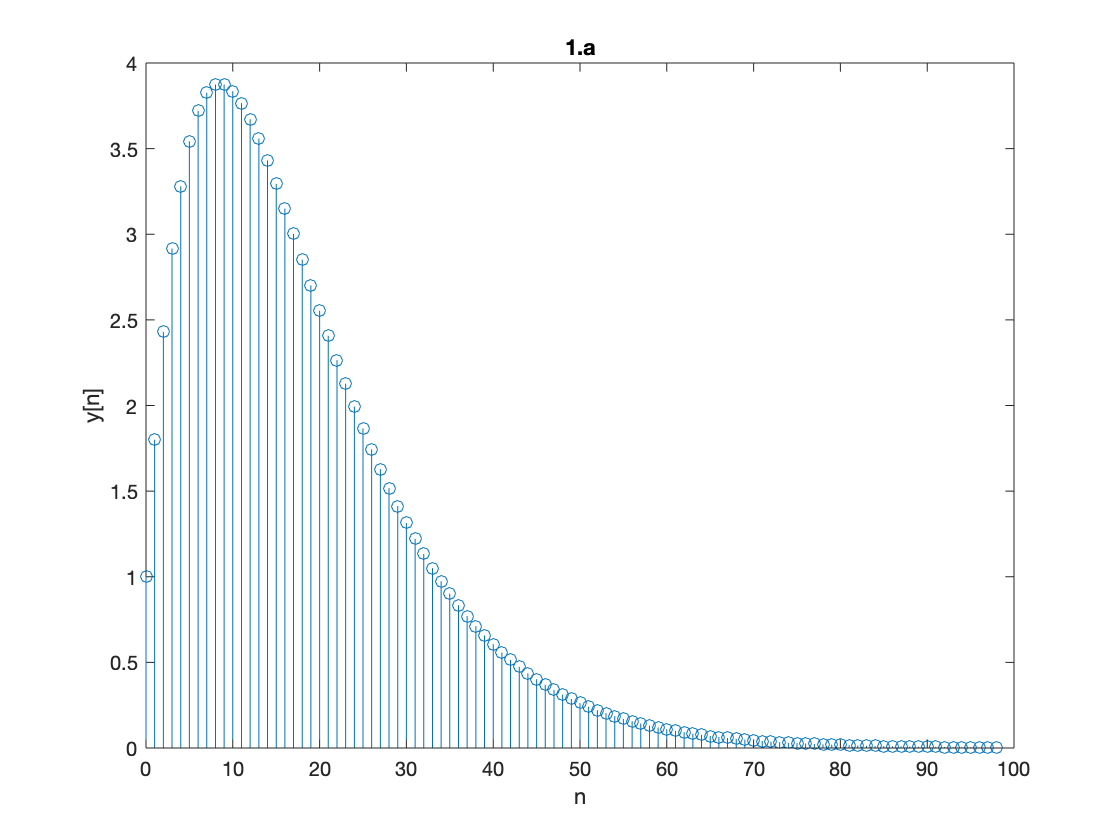

figure(1)
stem(n,y)
xlabel('n')
ylabel('y[n]')
title('1.a'); 

## 1.b

取前50個samples的x[n]和h[n]做convolution:


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack ={0\ldotp 9}^n \left(u\left\lbrack n\right\rbrack -u\left\lbrack 50\right\rbrack \right)\\
y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } {0\ldotp 9}^k \left(u\left\lbrack k\right\rbrack -u\left\lbrack k-50\right\rbrack \right){0\ldotp 9}^{n-k} \left(u\left\lbrack n-k\right\rbrack -u\left\lbrack n-k-50\right\rbrack \right)
\end{array}$$


將n設為0~49

a=0.9;
n=0:1:49;
u=heaviside(n);
u(n==0)=1 ;
x=(a.^n).*u

x =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057


h=(a.^n).*u

h =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057


將x[n]和h[n]做convolution，using conv function

conv 的output sequence 長度為x加上h的長度再減1

因此為50+50-1=99，設y[n]的n為ny，範圍為0~98

ny=0:1:98;
y = conv(x,h)

y =     1.0000    1.8000    2.4300    2.9160    3.2805    3.5429    3.7201    3.8264    3.8742    3.8742    3.8355    3.7657    3.6716    3.5586    3.4315    3.2943    3.1501    3.0019    2.8518    2.7017    2.5531    2.4072    2.2650    2.1271    1.9942    1.8665    1.7445    1.6282    1.5177    1.4130    1.3141    1.2209    1.1331    1.0507    0.9734    0.9011    0.8336    0.7705    0.7117    0.6569    0.6060    0.5587    0.5148    0.4741    0.4364    0.4015    0.3692    0.3393    0.3118    0.2863


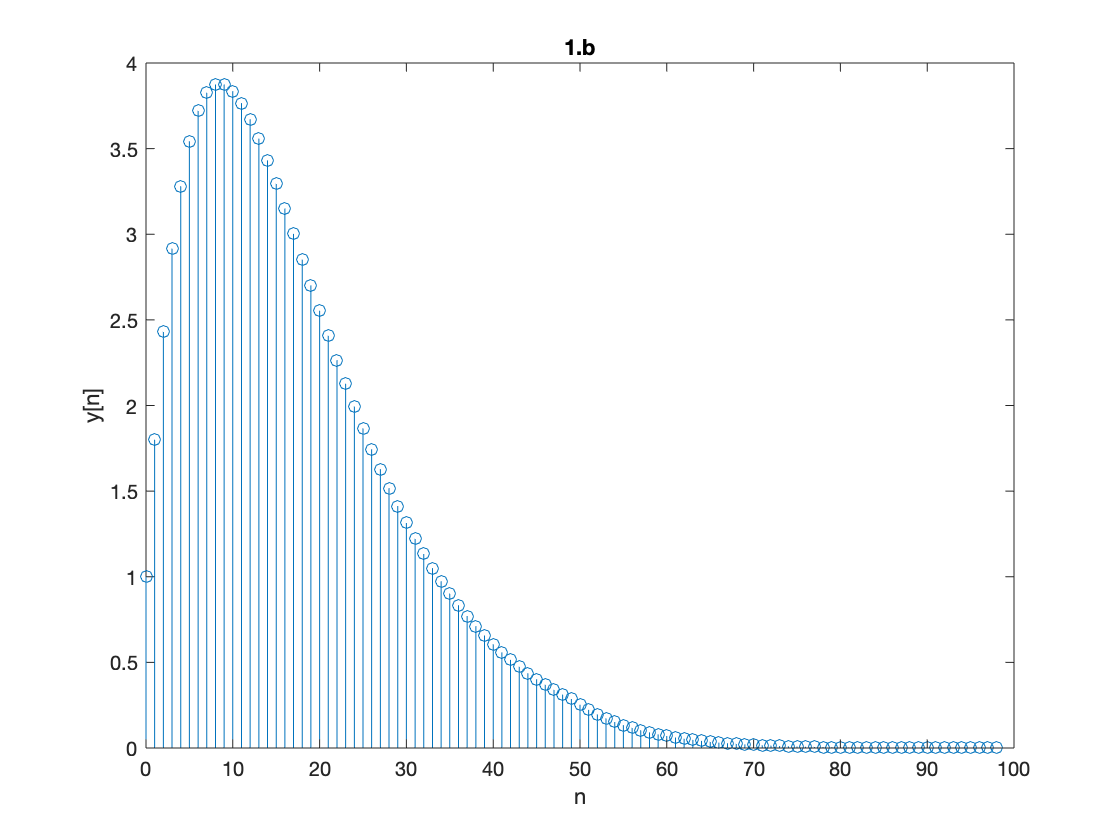

figure(2)
stem(ny,y)
xlabel('n')
ylabel('y[n]')
title('1.b'); 

## 1.c

h[n]經過transform後的到H(Z)：


$$\begin{array}{l}
h\left\lbrack n\right\rbrack ={0\ldotp 9}^n u\left\lbrack n\right\rbrack \\
H\left(Z\right)=\frac{1}{1-0\ldotp 9Z^{-1} }
\end{array}$$


filter fuction的output sequence y[n]長度等於input x[n]的長度，因此設n為0~98

w=0.9;
n=0:1:98;
u=heaviside(n);
u(n==0)=1 ;
x=(w.^n).*u

x =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057


filter function :

 using a rational transfer function defined by the numerator and denominator coefficients `b` and `a`.

b=1;
a=[1 -0.9];
y = filter(b,a,x,[],2)

y =     1.0000    1.8000    2.4300    2.9160    3.2805    3.5429    3.7201    3.8264    3.8742    3.8742    3.8355    3.7657    3.6716    3.5586    3.4315    3.2943    3.1501    3.0019    2.8518    2.7017    2.5531    2.4072    2.2650    2.1271    1.9942    1.8665    1.7445    1.6282    1.5177    1.4130    1.3141    1.2209    1.1331    1.0507    0.9734    0.9011    0.8336    0.7705    0.7117    0.6569    0.6060    0.5587    0.5148    0.4741    0.4364    0.4015    0.3692    0.3393    0.3118    0.2863


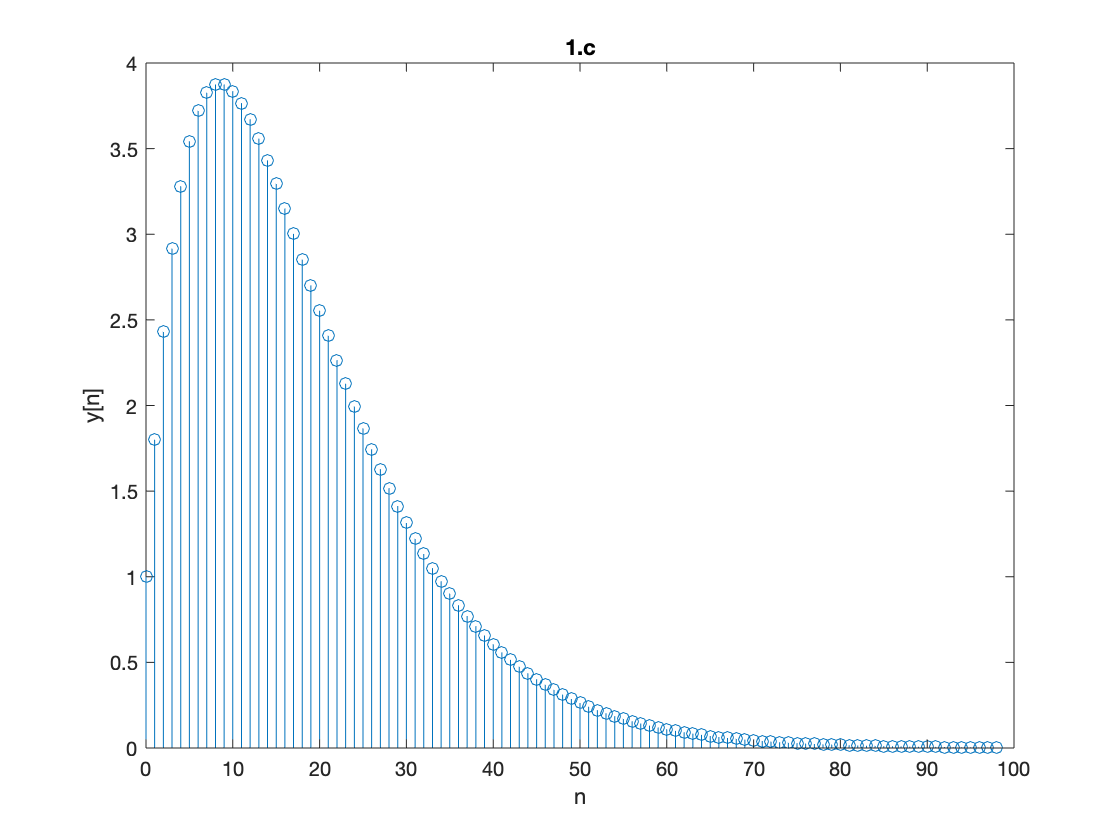

figure(3)
stem(n,y)
xlabel('n')
ylabel('y[n]')
title('1.c'); 

## 1.d

從圖形來看(a)~(c)都很相似，經過數值比較後 (c) filter is closer to (a)，

`filter` and `conv` is essentially the same except that `filter` keeps the output (y[n]) the same size as input (x[n]). 

So output with 99 samples, it can take input with 99 samples.

However, for conv , length of output is length of input x[n]+h[n]-1.

Output with 99 samples, and length of x[n]=h[n], so it can only take input (x[n]) with 50 samples.

Therefore,  filter is closer.

## 2.a

convulotion公式：


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \\
\Rightarrow \sum_{\infty } y\left\lbrack n\right\rbrack =\sum_{\infty } \sum_{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack \\
\Rightarrow \sum_n y\left\lbrack n\right\rbrack =\sum_n x\left\lbrack k\right\rbrack \sum_n h\left\lbrack n-k\right\rbrack \\
{\Rightarrow A}_y =A_x A_h 
\end{array}$$


## 2.b

x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h=ones(1,5);
y = conv(x,h)

y =     0.0527    0.1147    0.2639    0.5715    0.8902    1.0801    1.3955    1.7252    1.8227    2.0543    2.3960    2.6705    2.8358    3.0684    3.2350    3.5534    3.7394    3.9238    4.2644    4.5233    4.5284    4.7129    4.9220    4.8972    4.9465    5.0200    5.0583    4.9495    4.9579    4.9425    4.9081    4.8062    4.8689    4.7620    4.5419    4.4820    4.2720    4.0252    3.8256    3.5951    3.2484    3.1012    2.8173    2.5801    2.4043    2.2317    1.8866    1.6000    1.2645    0.9733



$$A_x =\sum_n x\left\lbrack n\right\rbrack \;\;,\;\;A_y =\sum_n y\left\lbrack n\right\rbrack \;\;\;\;A_h =\sum_n h\left\lbrack n\right\rbrack \;\;\;\;$$


x[n]sequnce長度為101，y[n]sequnce長度為105，h[n]sequnce長度為5

Ax= sum(x(1:101))

Ax = 0.3035

Ah = sum(h(1:5))

Ah = 5

Ay = sum(y(1:105))

Ay = 1.5177

將Ax與Ah相乘設為check，與上面計算出y[n]所得到的Ay做比較

check=Ax.*Ah

check = 1.5177

$A_y =A_x A_h \;\Rightarrow$   經過驗證，此式成立

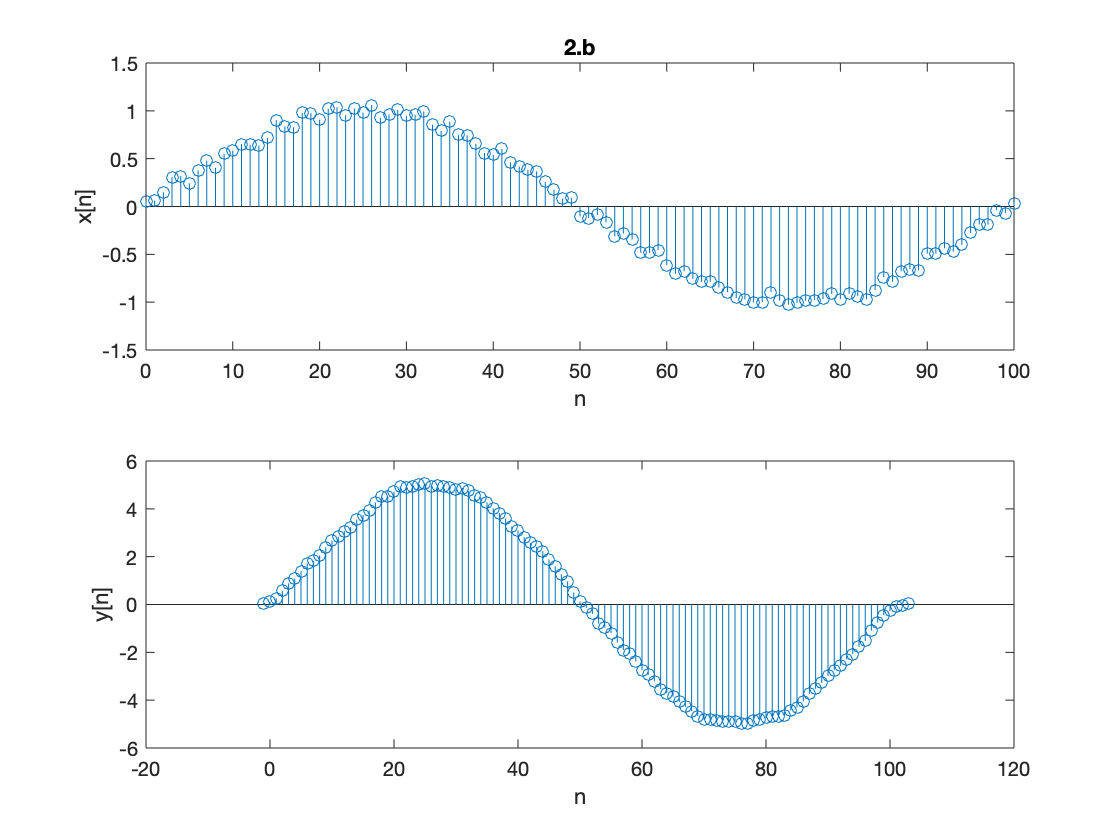

ny=-1:1:103;
nx=0:1:100;
figure(4)
subplot(2,1,1)
stem(nx,x)
xlabel('n')
ylabel('x[n]')
title('2.b'); 
subplot(2,1,2)
stem(ny,y)
xlabel('n')
ylabel('y[n]')

## 2.c

x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);

Ah=1，所以將原本的h除以sequence的長度=5

h=ones(1,5)/5

h =     0.2000    0.2000    0.2000    0.2000    0.2000


repeat part (b)

y = conv(x,h)

y =     0.0000    0.0235    0.0453    0.0825    0.1171    0.1819    0.2330    0.3016    0.3642    0.4300    0.4894    0.5684    0.6085    0.6639    0.7117    0.7402    0.7443    0.7948    0.8210    0.8674    0.9030    0.9273    0.9407    0.9571    0.9682    0.9677    0.9670    0.9755    0.9665    0.9496    0.9574    0.9624    0.9420    0.9404    0.9311    0.8972    0.8599    0.8111    0.7641    0.7352    0.7014    0.6620    0.6135    0.5463    0.4640    0.3604    0.3049    0.2694    0.2227    0.1637


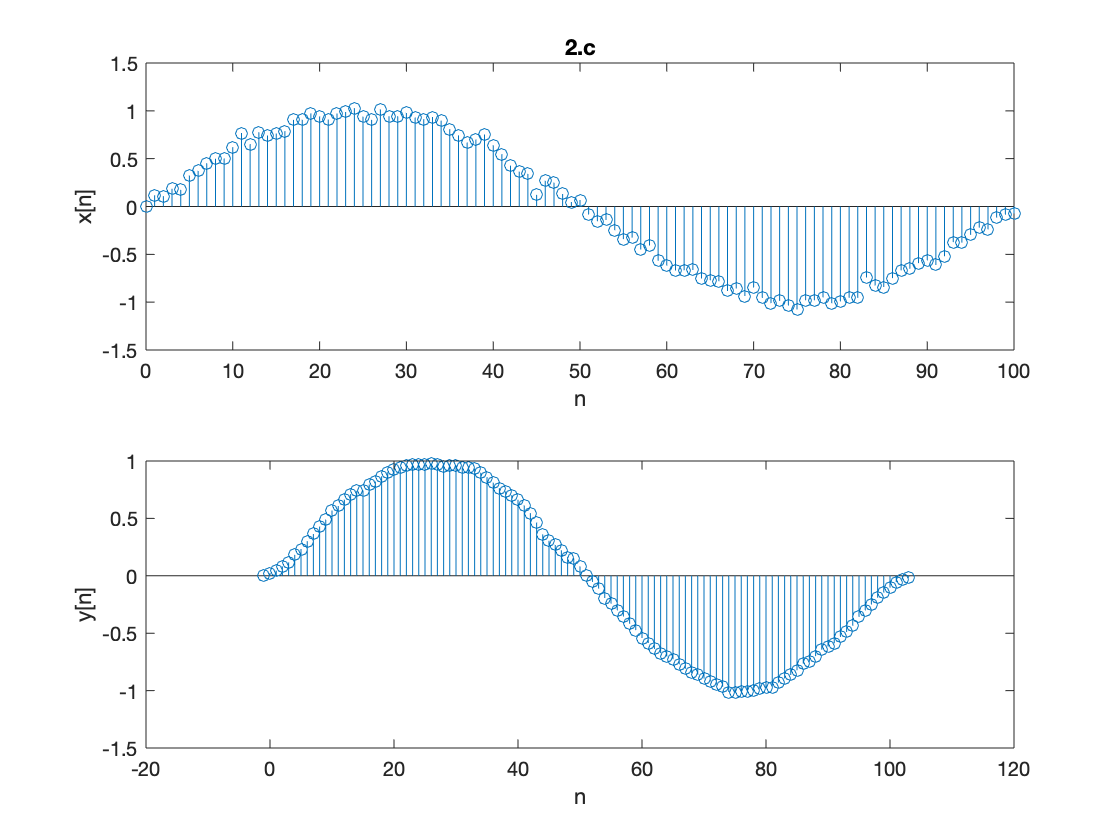

ny=-1:1:103;
nx=0:1:100;

figure(5)
subplot(2,1,1)
stem(nx,x)
xlabel('n')
ylabel('x[n]')
title('2.c'); 
subplot(2,1,2)
stem(ny,y)
xlabel('n')
ylabel('y[n]')

Ax= sum(x(1:101))

Ax = 0.1673

Ah = sum(h(1:5))

Ah = 1

Ay = sum(y(1:105))

Ay = 0.1673

將Ax與Ah相乘設為check，與上面計算出y[n]所得到的Ay做比較

check=Ax.*Ah

check = 0.1673

$A_y =A_x A_h \;\;\Rightarrow$   經過驗證，此式成立

## 2.d


$$A_y =A_x A_h \;\;$$


If$Ａ_h =1,{\;\textrm{then}\;A}_y =A_h$

$Ａ_y$與$Ａ_h$成正比，所以當h[n]的總合越大時，$Ａ_y$就越大

因此經過Normalize的h[n]所產生的$Ａ_y$就會比未Normalize的$Ａ_y$小

x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h1=ones(1,5);
h2=ones(1,5)/5;
y1 = conv(x,h1);
y2 = conv(x,h2);

將(b)和(c)所得到的y[n]做比較

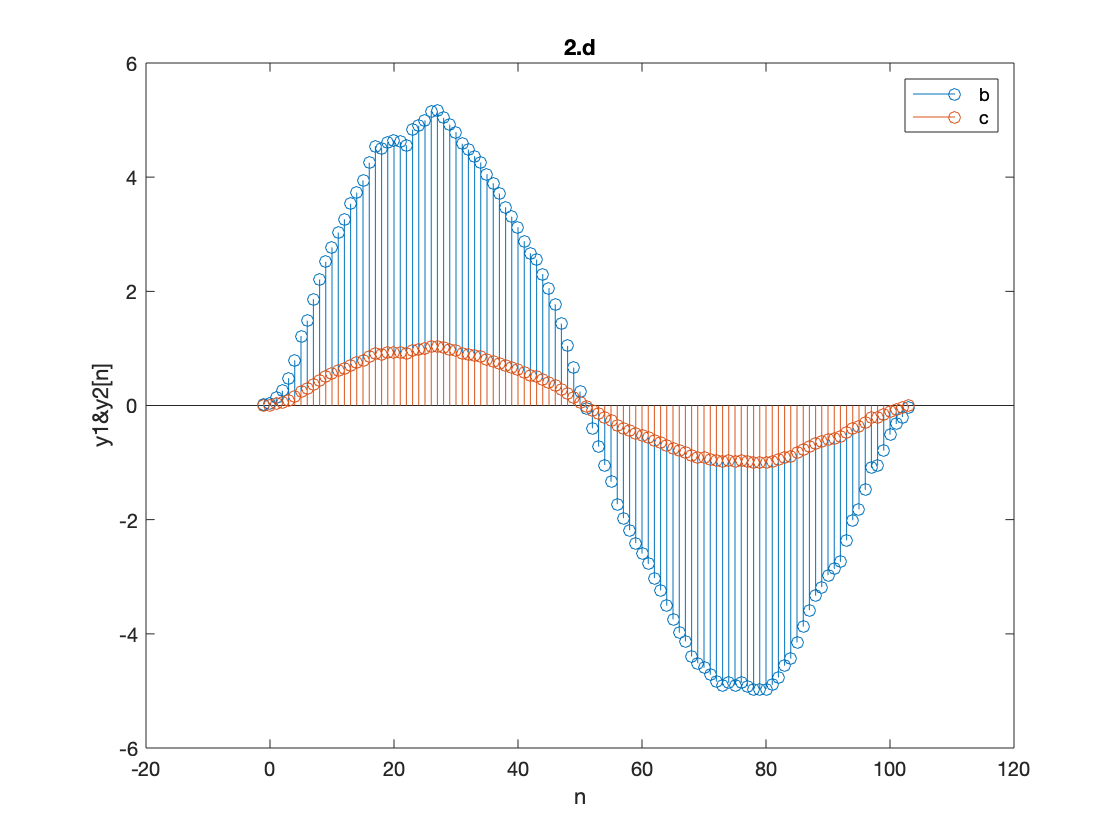

ny=-1:1:103;

figure(6)
stem(ny,y1)
hold on
stem(ny,y2)
hold off
xlabel('n')
ylabel('y1&y2[n]')
title('2.d'); 
legend('b','c');

## 3.a


$$\begin{array}{l}
H\left(Z\right)=\frac{Y\left(Z\right)}{X\left(Z\right)}\\
X\left(Z\right)=\frac{1}{1-Z^{-1} }\;\;,\;Y\left(Z\right)=\frac{2}{1-\left(\frac{1}{3}\right)Z^{-1} }\\
H\left(Z\right)=\frac{2\left(1-Z^{-1} \right)}{1-\left(\frac{1}{3}\right)Z^{-1} }
\end{array}$$


上面是推算出來的H(Z)，先經過filter檢驗結果y2[n]與題目的y1[n]是否相同

a=1/3;
n=0:1:49;
u=heaviside(n);
u(n==0)=1 ;
x=u;
y1=2.*(a.^n).*u

y1 =     2.0000    0.6667    0.2222    0.0741    0.0247    0.0082    0.0027    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


b=[2 , -2];
a=[1 ,-1/3];
y2 = filter(b,a,x,[],2)

y2 =     2.0000    0.6667    0.2222    0.0741    0.0247    0.0082    0.0027    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


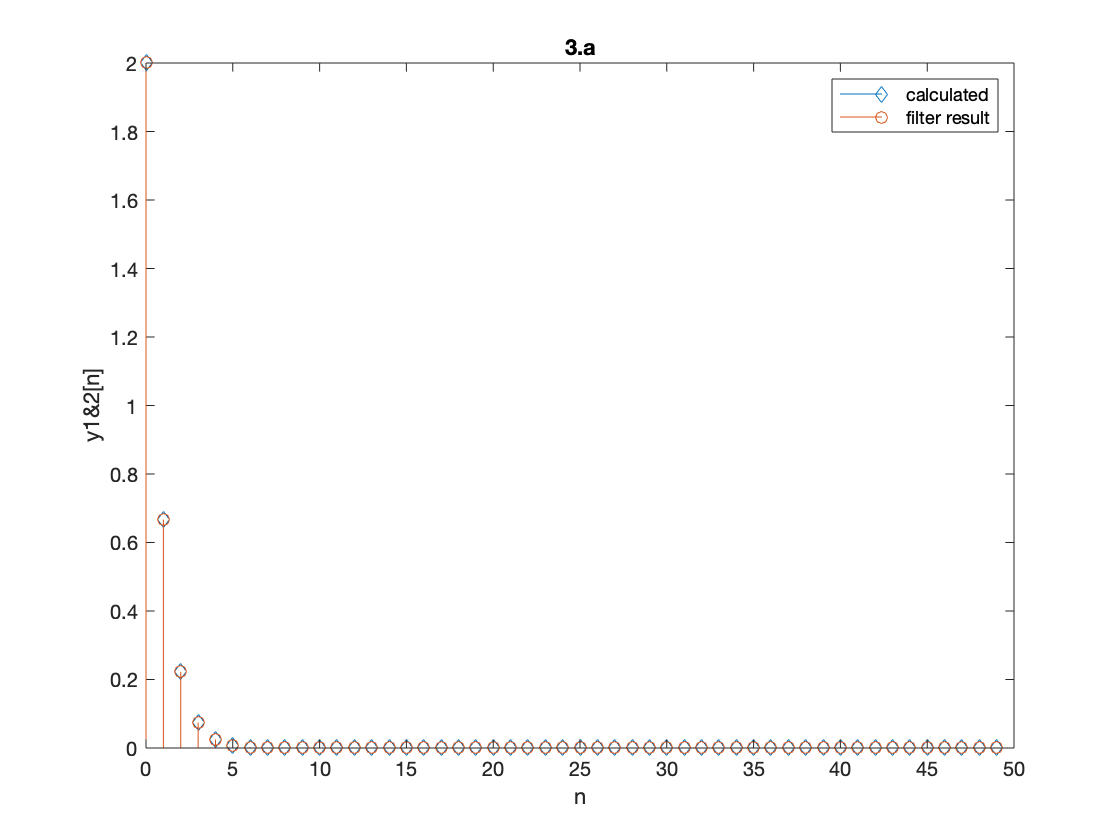

figure(7)
stem(n,y1,"diamond")
hold on
stem(n,y2)
hold off
xlabel('n')
ylabel('y1&2[n]')
title('3.a'); 
legend('calculated','filter result');

y1[n]和y2[n]經過數值與圖形比對完全相等，因此推算出的H(Z)是正確的。

設定一個input為$\delta \left\lbrack n\right\rbrack$，經過filter後可得到h[n]

n=0:1:49;
x = dirac(n);
idx = x == Inf; % find Inf
x(idx) = 1;     % set Inf to finite value

b=[2 , -2];
a=[1 ,-1/3];
h = filter(b,a,x,[],2)

h =     2.0000   -1.3333   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


## 3.b

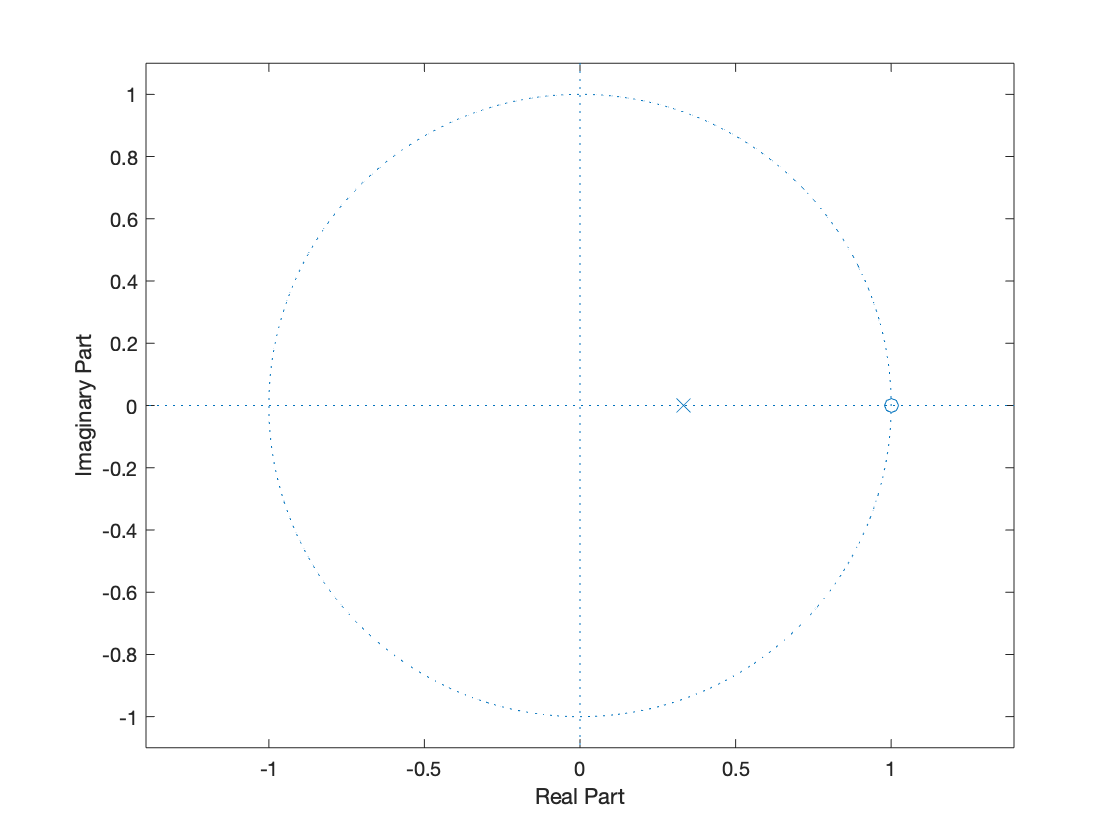

b=[2 , -2];
a=[1 ,-1/3];
zplane(b,a)

## 3.c

與3.b相同


$$\begin{array}{l}
H\left(Z\right)=\frac{Y\left(Z\right)}{X\left(Z\right)}\\
X\left(Z\right)=\frac{1}{1-Z^{-1} }\;\;,\;Y\left(Z\right)=\frac{2}{1-\left(\frac{1}{3}\right)Z^{-1} }\\
H\left(Z\right)=\frac{2\left(1-Z^{-1} \right)}{1-\left(\frac{1}{3}\right)Z^{-1} }
\end{array}$$


n=0:1:49;
x = dirac(n);
idx = x == Inf; % find Inf
x(idx) = 1;     % set Inf to finite value

b=[2 , -2];
a=[1 ,-1/3];
h = filter(b,a,x,[],2)

h =     2.0000   -1.3333   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


上面是經過filter產生的h[n]，下方再與impz做比較

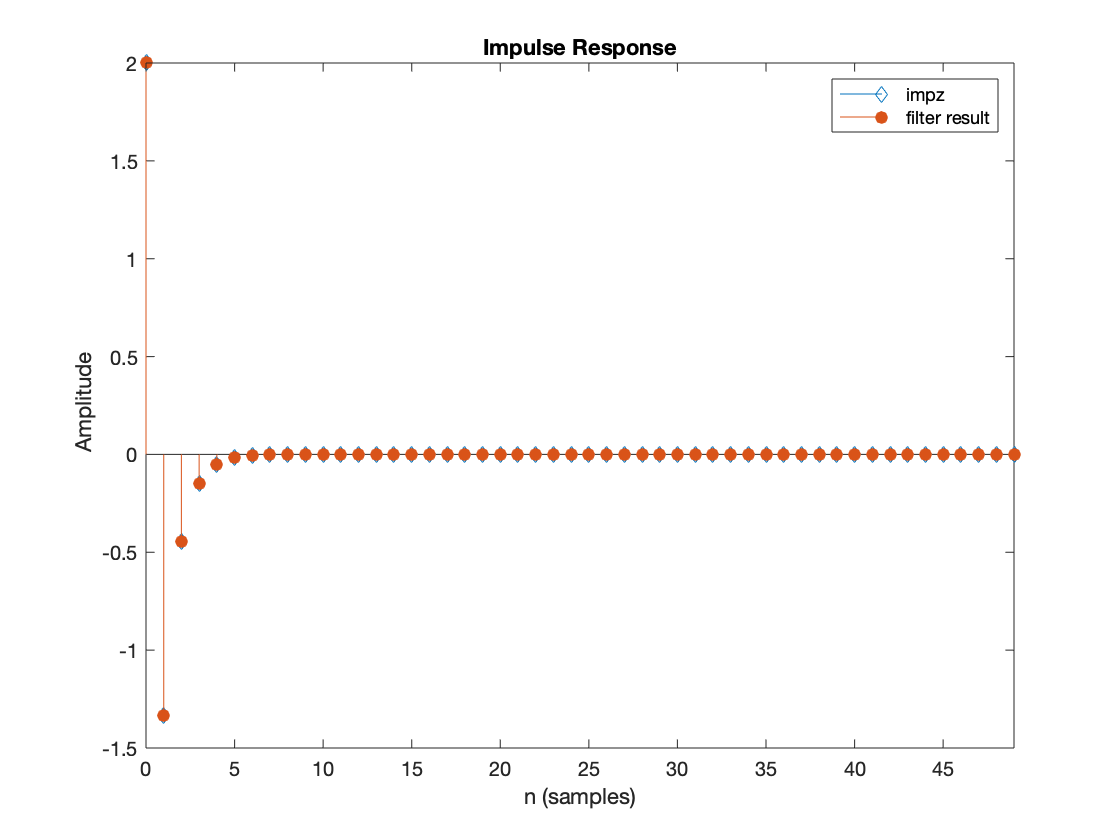

figure(8)
stem(n,h,"diamond")
hold on
title('3.c');
impz(b,a,50)
hold off
legend('impz','filter result');

將經過filter得到的h[n]與impz的做比較，兩者數值完全相等，表示經過filter得到的h[n]是正確的

## 3.d


$$H\left(Z\right)=\frac{2\left(1-Z^{-1} \right)}{1-\left(\frac{1}{3}\right)Z^{-1} }$$


b0 = 2;
b1 = [1  -1];
a = [1 -1/3];
b = b0*b1;
[r,p,k] = residuez(b,a)

r = -4

p = 0.3333

k = 6

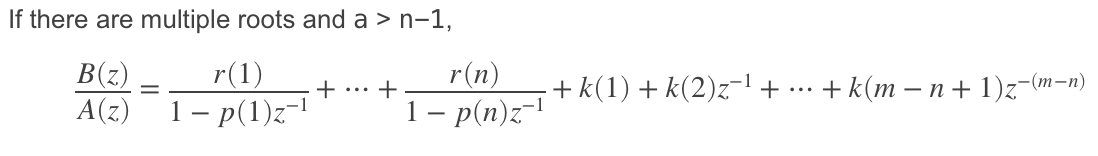

利用residuez所得結果可推出H(Z)為：


$$H\left(Z\right)=\frac{-4}{1-\left(0\ldotp 3333\right)Z^{-1} }+6$$


再推出h[n]為：


$$h\left\lbrack n\right\rbrack =-4{\left(0\ldotp 3333\right)}^n \;\;u\left\lbrack n\right\rbrack +6\delta \left\lbrack n\right\rbrack$$


將推算出的h設為h1與impz產生的h2做比較：

n=0:1:49;
x = dirac(n);
idx = x == Inf; % find Inf
x(idx) = 1; 
h1=-4*(0.3333).^n+6*x

h1 =     2.0000   -1.3332   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


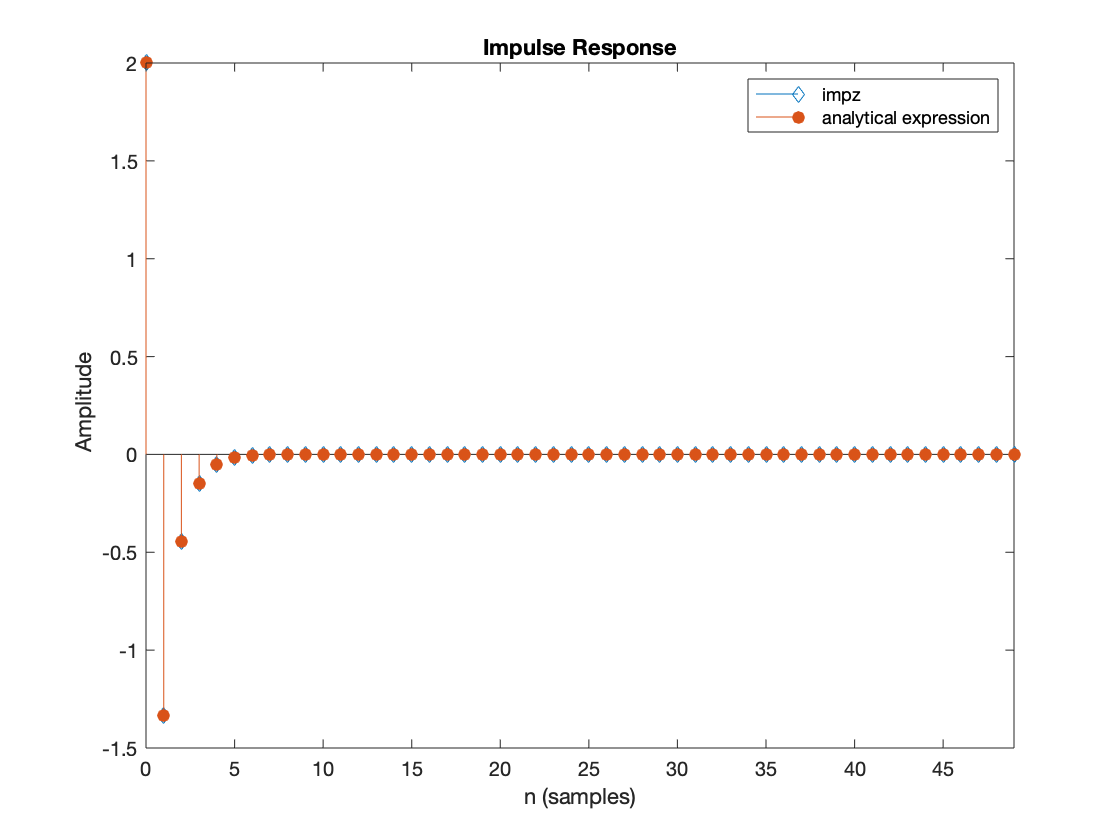

b=[2 , -2];
a=[1 ,-1/3];
figure(9)
stem(n,h1,"diamond")
hold on
impz(b,a,50)
hold off
legend('impz','analytical expression');

將推算出的h[n]與impz的做比較，兩者數值完全相等，表示推算的h[n]是正確的

## 4.


$$H\left(Z\right)=\frac{b_0 +b_1 Z^{-1} }{1+a_1 Z^{-1} +a_2 Z^{-2} }$$


設定real and equal poles at $\pm 0\ldotp 25/\pm 0\ldotp 5/\pm 1/\pm 2/\pm 3$，再用impz做圖觀察：

for double poles at $+0\ldotp 25$

b=[1];
a1=[1 ,-0.25];
a2=[1 ,-0.25];
a=conv(a1,a2)

a =     1.0000   -0.5000    0.0625



$$a_1 =-0\ldotp 5$$


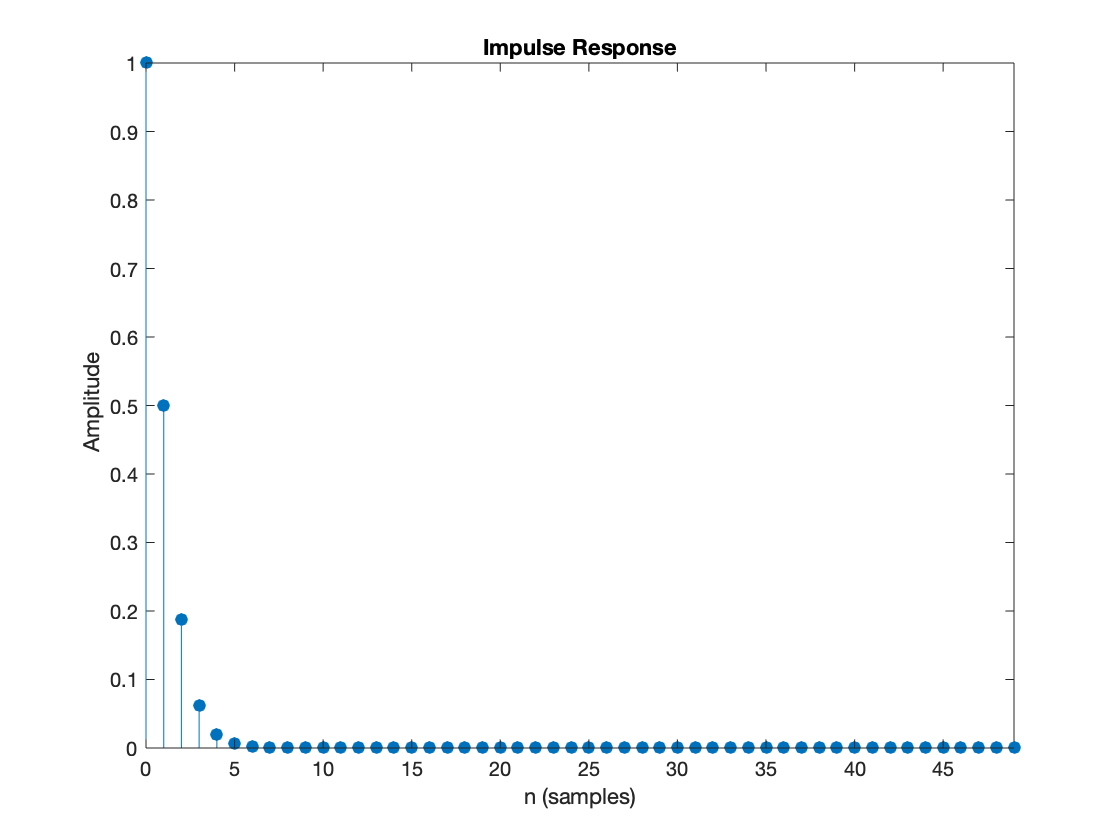

impz(b,a,50)

for double poles at $-0\ldotp 25$

b=[1];
a1=[1 ,0.25];
a2=[1 ,0.25];
a=conv(a1,a2)

a =     1.0000    0.5000    0.0625



$$a_1 =0\ldotp 5$$


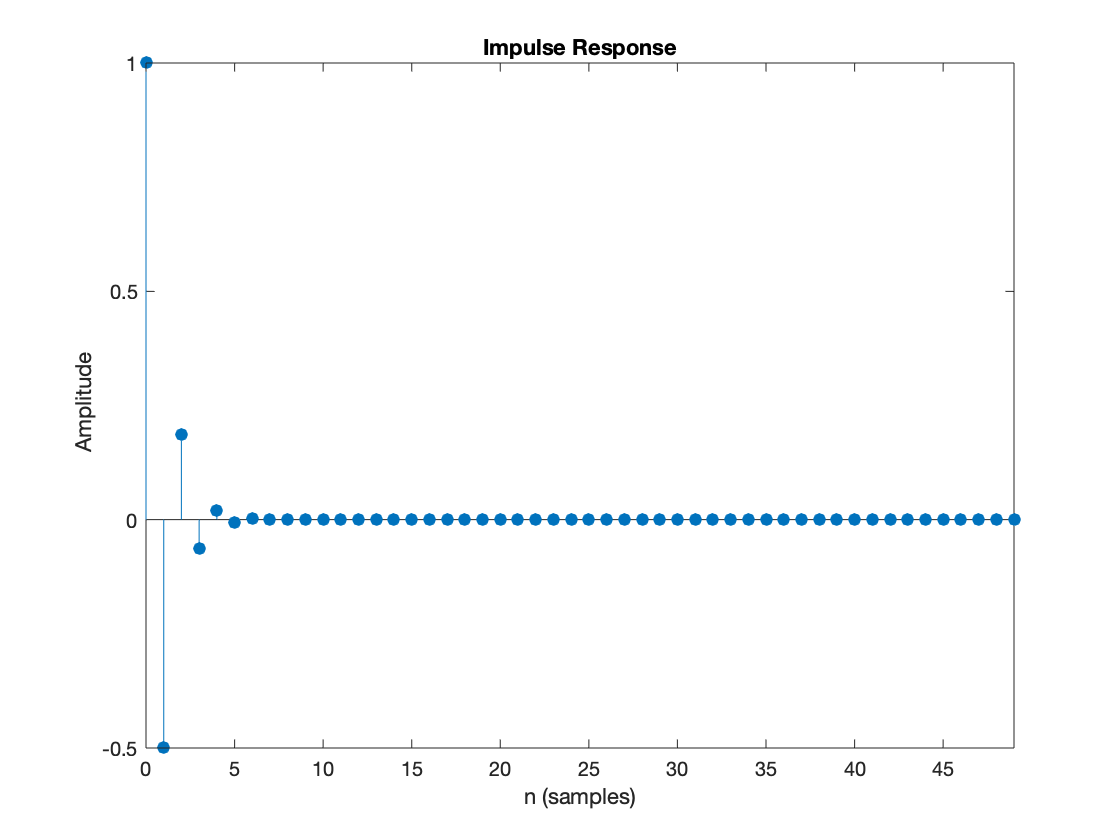

impz(b,a,50)

for double poles at $+0\ldotp 5$

b=[1];
a1=[1 ,-0.5];
a2=[1 ,-0.5];
a=conv(a1,a2)

a =     1.0000   -1.0000    0.2500



$$a_1 =-1$$


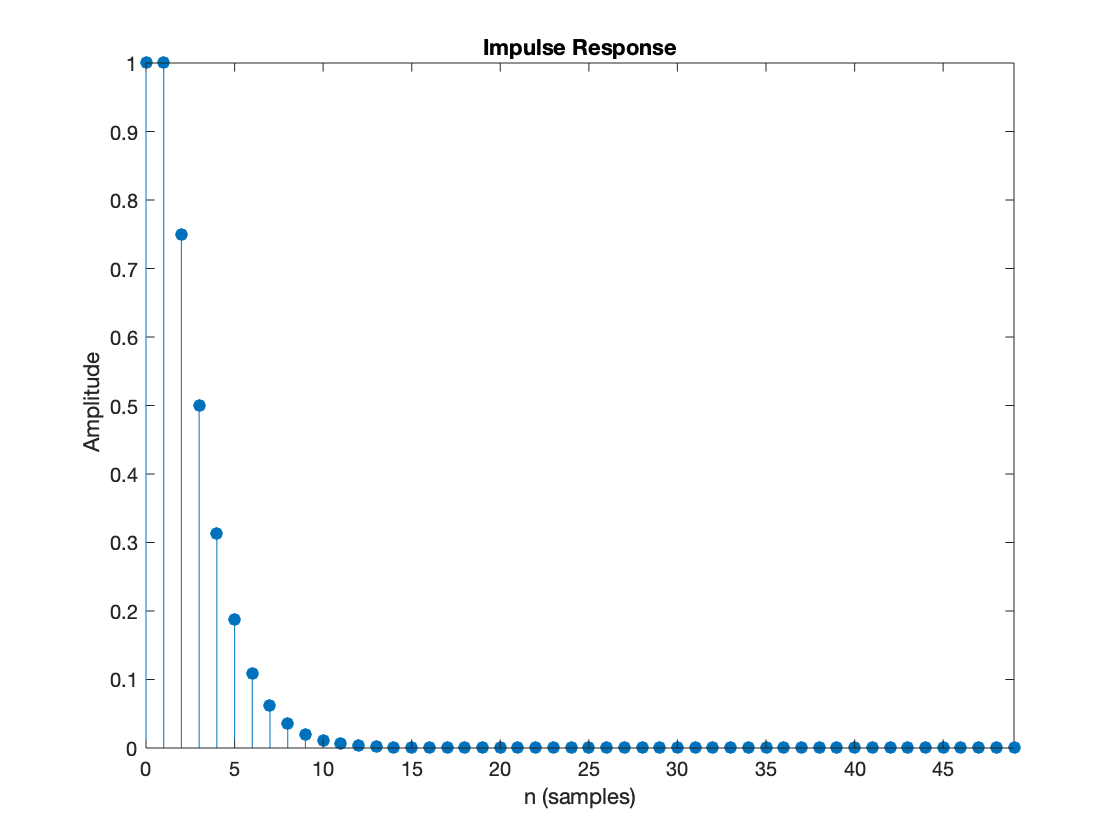

impz(b,a,50)

for double poles at $-0\ldotp 5$

b=[1];
a1=[1 ,0.5];
a2=[1 ,0.5];
a=conv(a1,a2)

a =     1.0000    1.0000    0.2500



$$a_1 =1$$


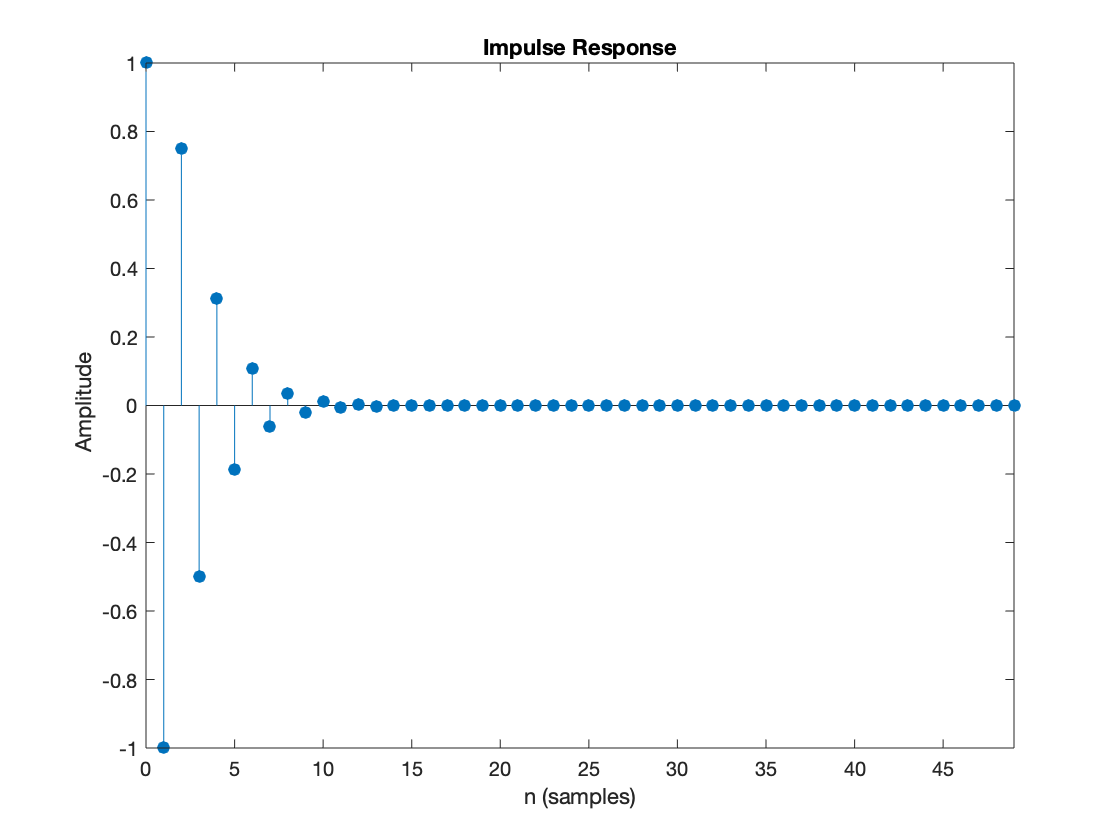

impz(b,a,50)

for double poles at $+1$

b=[1];
a1=[1 ,-1];
a2=[1 ,-1];
a=conv(a1,a2)

a =      1    -2     1



$$a_1 =-2$$


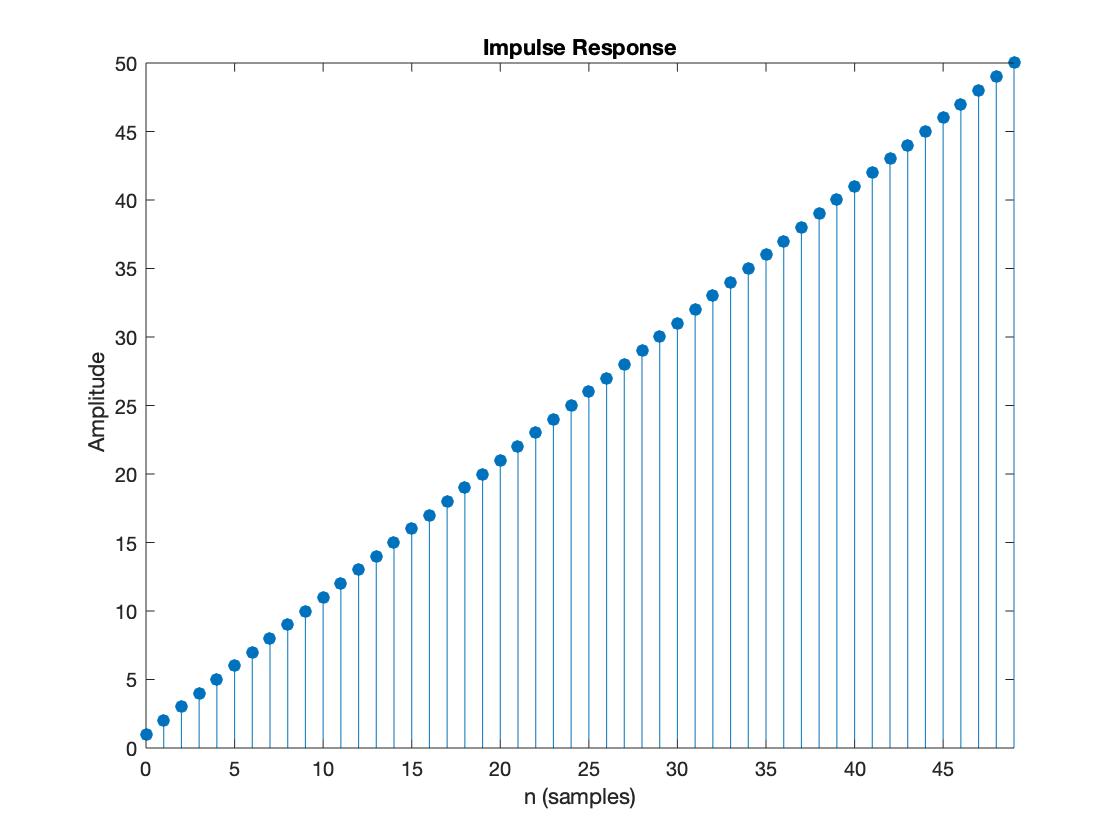

impz(b,a,50)

for double poles at $-1$

b=[1];
a1=[1 ,1];
a2=[1 ,1];
a=conv(a1,a2)

a =      1     2     1



$$a_1 =2$$


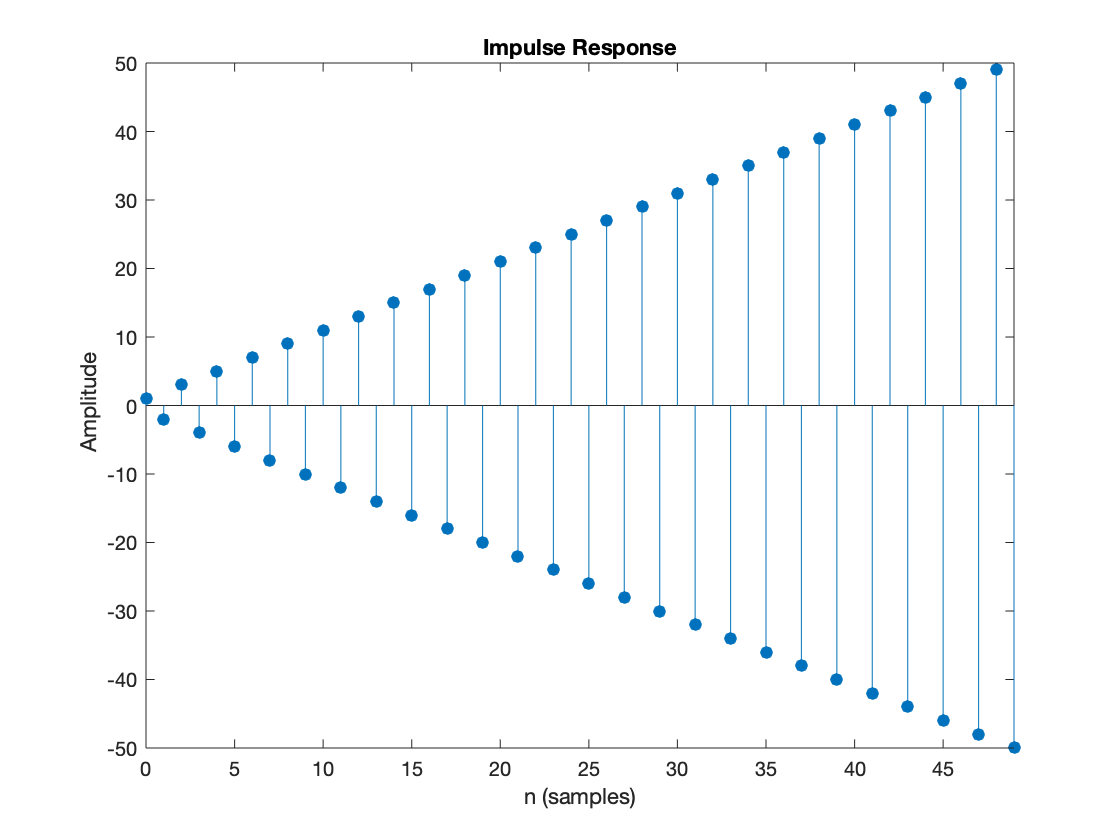

impz(b,a,50)

for double poles at $+2$

b=[1];
a1=[1 ,-2];
a2=[1 ,-2];
a=conv(a1,a2)

a =      1    -4     4



$$a_1 =-4$$


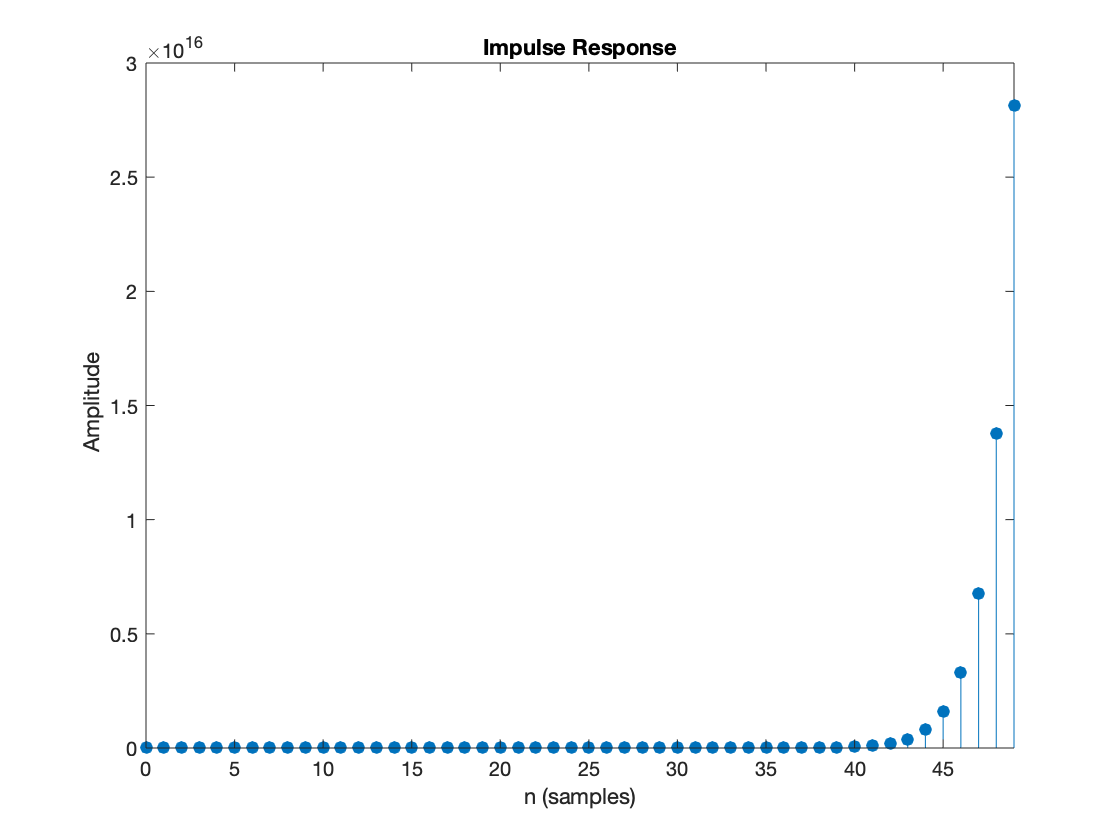

impz(b,a,50)

for double poles at $-2$

b=[1];
a1=[1 ,2];
a2=[1 ,2];
a=conv(a1,a2)

a =      1     4     4



$$a_1 =4$$


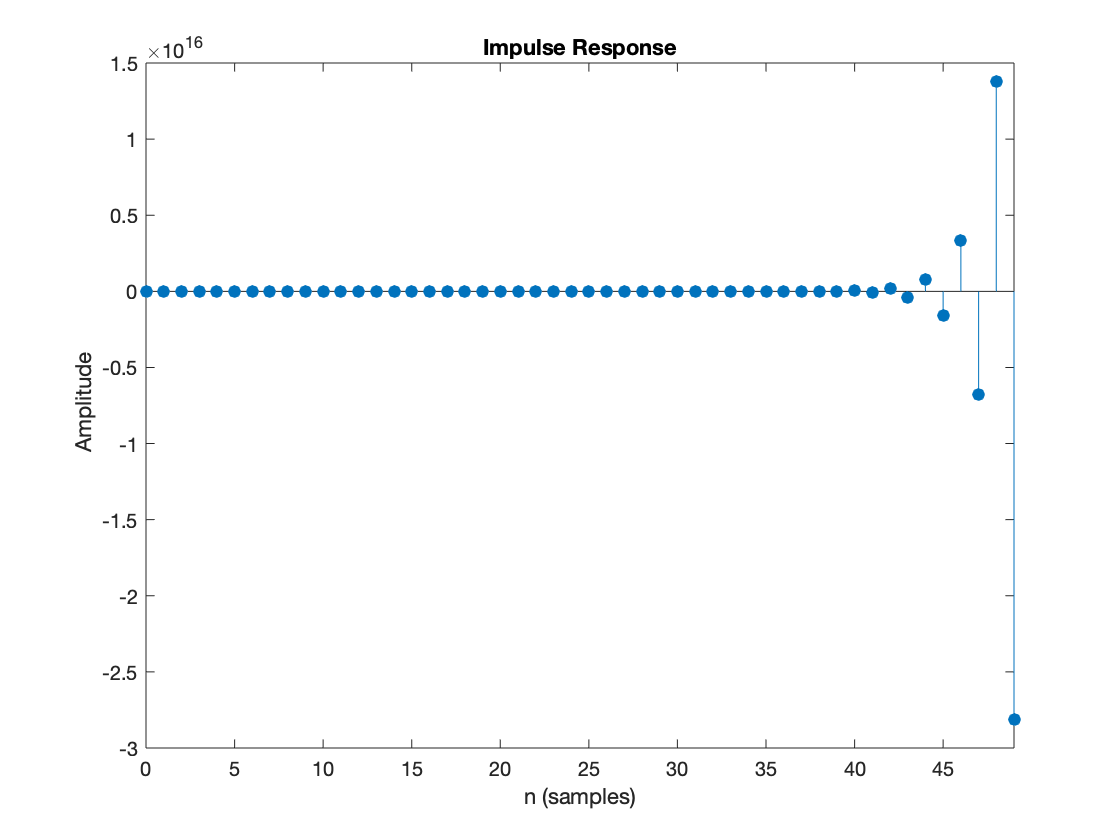

impz(b,a,50)

for double poles at $+3$

b=[1];
a1=[1 ,-3];
a2=[1 ,-3];
a=conv(a1,a2)

a =      1    -6     9



$$a_1 =-6$$


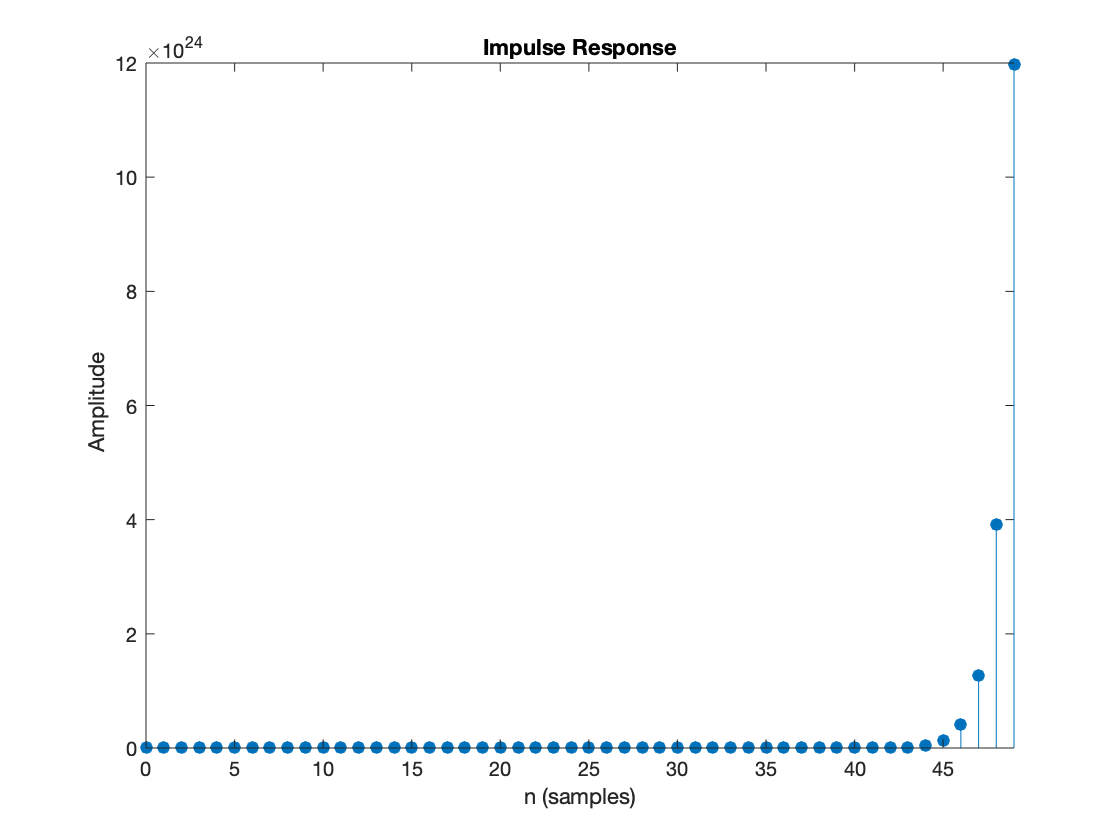

impz(b,a,50)

for double poles at $-3$

b=[1];
a1=[1 ,3];
a2=[1 ,3];
a=conv(a1,a2)

a =      1     6     9



$$a_1 =6$$


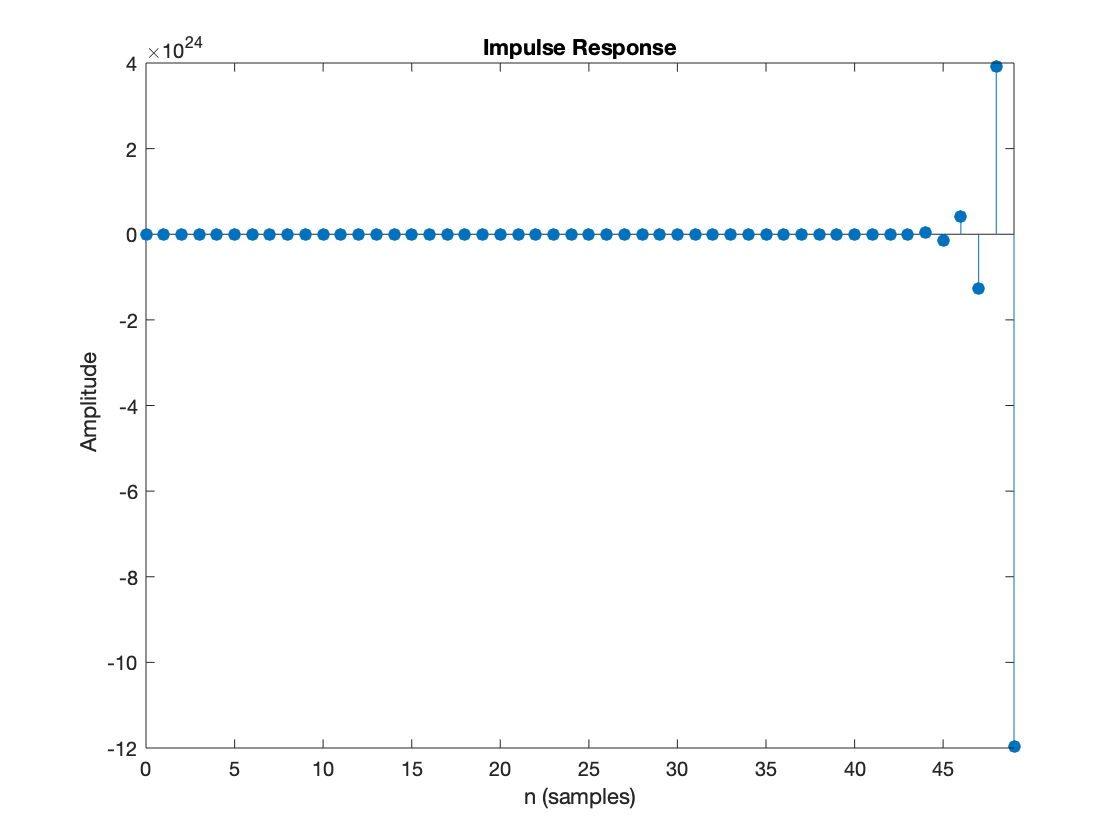

impz(b,a,50)

## 4.a


$$H\left(Z\right)=\frac{b_0 +b_1 Z^{-1} }{1+a_1 Z^{-1} +a_2 Z^{-2} }$$


從impulse response的圖可看出，

當|a1| = 1，the system is stable，

當|a1| $>$ 1，the system is not stable，

當|a1| $<$ 1，the system is stable.

## 4.b

從impulse response的圖觀察，

當a1 $>$ 0，impulse response會每個點正負交替，

當a1 $<$ 0，impulse response每個點皆大於0，

當|a1| $<$ 1，impulse response會慢慢收斂，且|a1|越小amplitude收斂越快

當|a1| = 2，impulse response為一直線上升或下降

當|a1| $>$ 1，impulse response會慢慢發散，|a1|越大amplitude發散越快，且發散起點n越大

## 5.a

將y[n]做One-sided z-transform：


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =2\mathrm{cos}\left(\omega_0 \right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack \\
\iff Y\left(Z\right)=2\mathrm{cos}\left(\omega_0 \right)\left(Z^{-1} Y\left(Z\right)\mathrm{＋y}\left\lbrack -1\right\rbrack \right)-\left(Z^{-2} Y\left(Z\right)+Z^{-1} y\left\lbrack -1\right\rbrack +y\left\lbrack -2\right\rbrack \right)\\
y\left\lbrack -1\right\rbrack =0\;,y\left\lbrack -2\right\rbrack =-\mathrm{Asin}\left(\omega_0 \right)\;,\mathrm{so}:\\
Y\left(Z\right)=2\mathrm{cos}\left(\omega_0 \right)Z^{-1} Y\left(Z\right)-Z^{-2} Y\left(Z\right)+\mathrm{Asin}\left(\omega_0 \right)\\
\Rightarrow \left(1-2\mathrm{cos}\left(\omega_0 \right)Z^{-1} +Z^{-2} \right)Y\left(Z\right)=\mathrm{Asin}\left(\omega_0 \right)\\
\Rightarrow Y\left(Z\right)=\frac{\mathrm{Asin}\left(\omega_0 \right)}{\left(1-2\mathrm{cos}\left(\omega_0 \right)Z^{-1} +Z^{-2} \right)}\\
\Rightarrow Y\left(Z\right)=\frac{\mathrm{Asin}\left(\omega_0 \right)Z^{-1} }{\left(1-2\mathrm{cos}\left(\omega_0 \right)Z^{-1} +Z^{-2} \right)}Z\\
\iff y\left\lbrack n\right\rbrack =\mathrm{Asin}\left\lbrack \left(n+1\right)\omega_0 \right\rbrack u\left\lbrack n+1\right\rbrack \\
\mathrm{when}\;n=-1\;,\;y\left\lbrack n\right\rbrack =0\\
\mathrm{so}\;y\left\lbrack n\right\rbrack \;\mathrm{can}\;\mathrm{be}:\\
y\left\lbrack n\right\rbrack =\mathrm{Asin}\left\lbrack \left(n+1\right)\omega_0 \right\rbrack u\left\lbrack n\right\rbrack 
\end{array}$$


## 5.b

設filter產生出來的y為y1

n=0:1:49;
w=0.1*pi;
A=2;

b = [0];
a=[1 -2*cos(w) 1];
yic = [0 -A*sin(w)];
xic = [0];
zic = filtic(b, a, yic, xic);
y1 = filter(b, a, x, zic)

y1 =     0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180   -0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180    0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180   -0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180    0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180   -0.0000


將推導結果的y設為y2：


$$y_2 \left\lbrack n\right\rbrack =A*\sin \left\lbrack \left(n+1\right)w_0 \right\rbrack u\left\lbrack n\right\rbrack$$


u=heaviside(n);
u(n==0)=1 ;
y2=A.*sin((n+1).*w).*u

y2 =     0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000


將做比較：

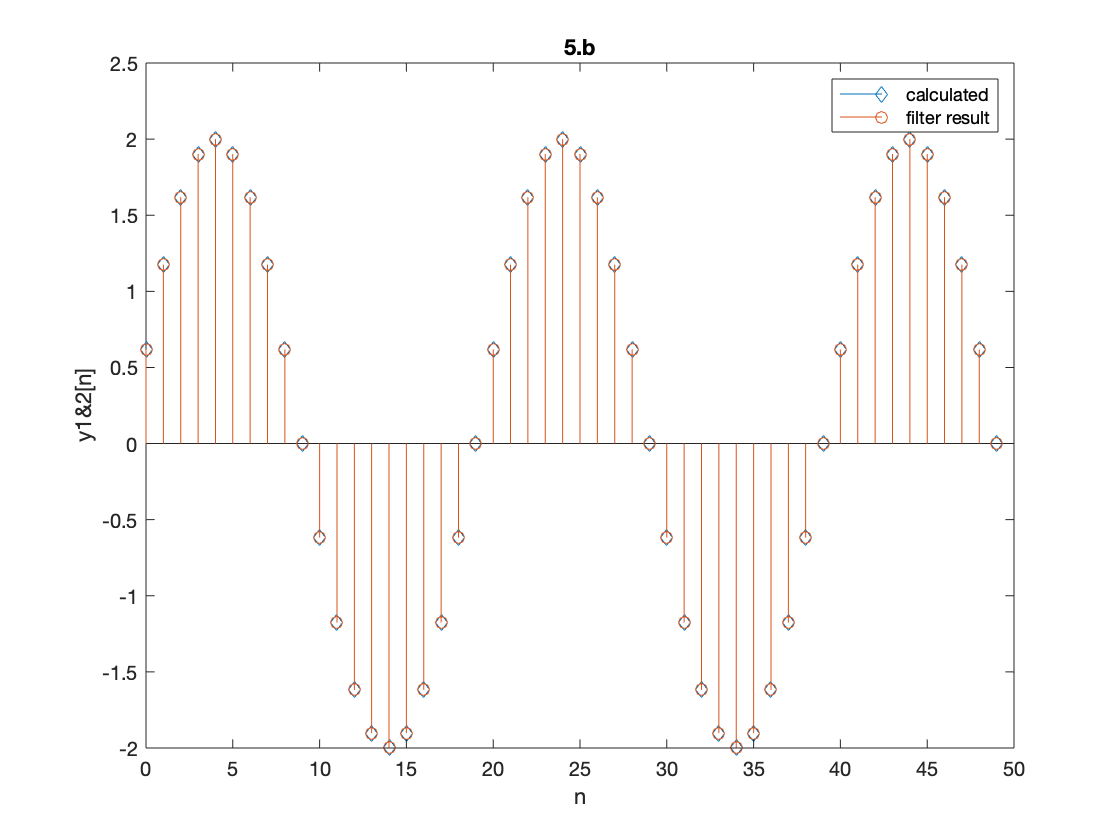

figure(10)
stem(n,y1,"diamond")
hold on
stem(n,y2)
hold off
xlabel('n')
ylabel('y1&2[n]')
title('5.b'); 
legend('calculated','filter result');

y1==y2

ans = 1×50 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


經過數值驗證，兩者完全相等，可得推討結果正確

## 6.a

DTFS coefficients 公式：


$$C_k =\frac{1}{N}\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-j\frac{2\pi }{N}\mathrm{kn}}$$


Write a function c=dtfs0(x)：

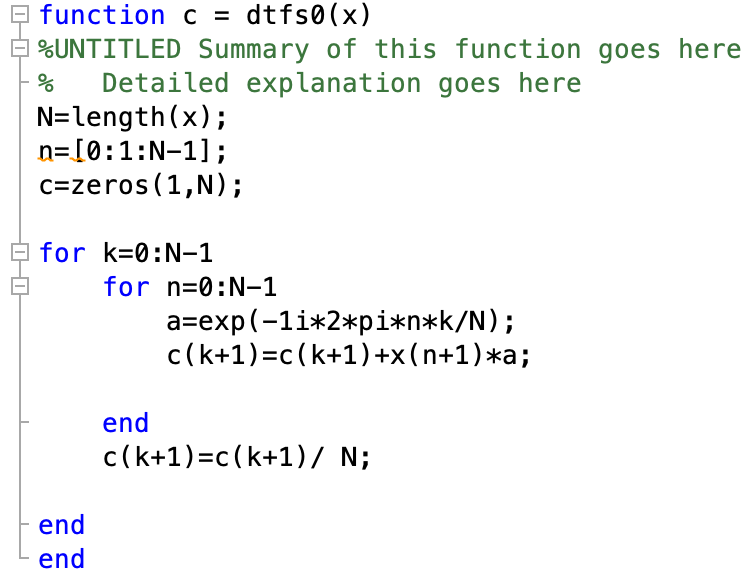

設定一組input g[n]，代入function dtfs0與dtfs做比較：

n=0:1:9;
g=[1 1 1 0 0 0 0 0 1 1]

g =      1     1     1     0     0     0     0     0     1     1


c1=dtfs0(g)

c1 =    0.5000 + 0.0000i   0.3236 + 0.0000i  -0.0000 - 0.0000i  -0.1236 - 0.0000i   0.0000 - 0.0000i   0.1000 + 0.0000i  -0.0000 - 0.0000i  -0.1236 - 0.0000i   0.0000 - 0.0000i   0.3236 + 0.0000i


c2=dtfs(g)

c2 =     0.5000    0.3236         0   -0.1236         0    0.1000         0   -0.1236         0    0.3236


dtfs0與dtfs所得到的coefficients分別為c1和c2，下方將c1和c2的實虛部分開做比較，只將虛部取到小數點後5位做比較：

c1r=real(c1)

c1r =     0.5000    0.3236   -0.0000   -0.1236    0.0000    0.1000   -0.0000   -0.1236    0.0000    0.3236


c2r=real(c2)

c2r =     0.5000    0.3236         0   -0.1236         0    0.1000         0   -0.1236         0    0.3236


c1i=imag(c1);
c1i=roundn(c1i,-5)

c1i =      0     0     0     0     0     0     0     0     0     0


c2i=imag(c2)

c2i =      0     0     0     0     0     0     0     0     0     0


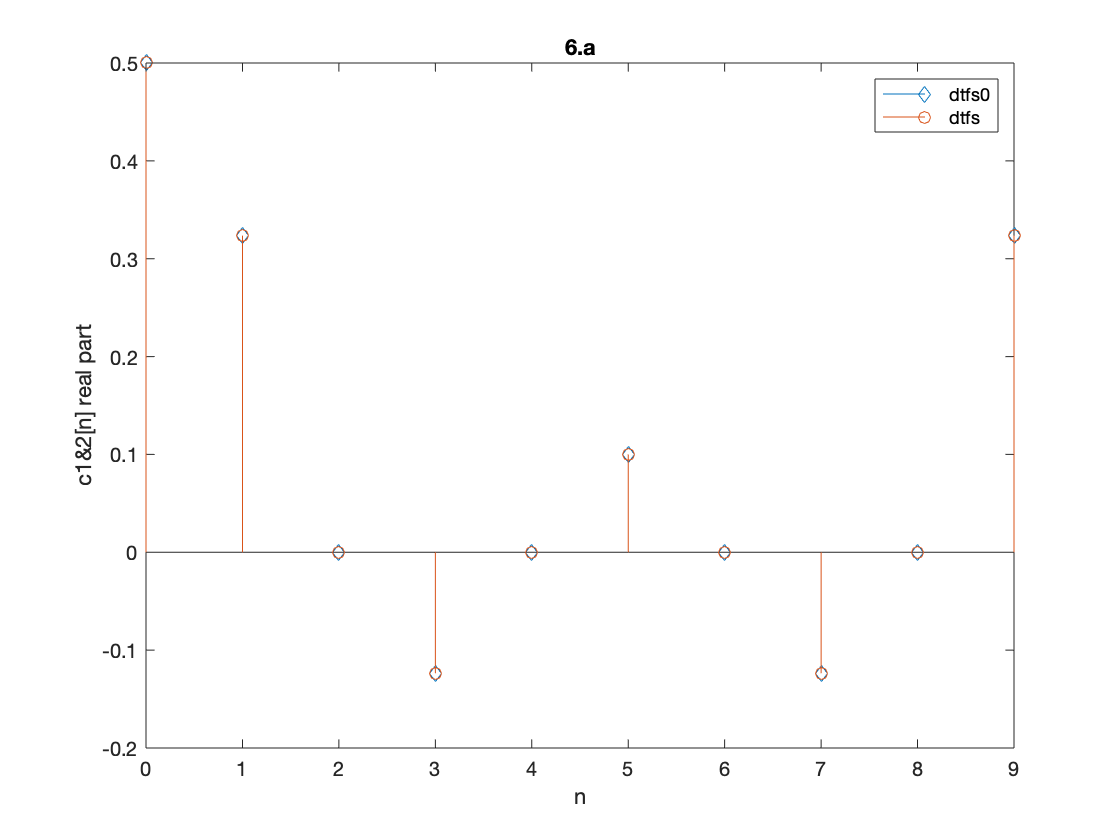

figure(11)
stem(n,c1r,"diamond")
hold on
stem(n,c2r)
hold off
xlabel('n')
ylabel('c1&2[n] real part')
title('6.a'); 
legend('dtfs0','dtfs');

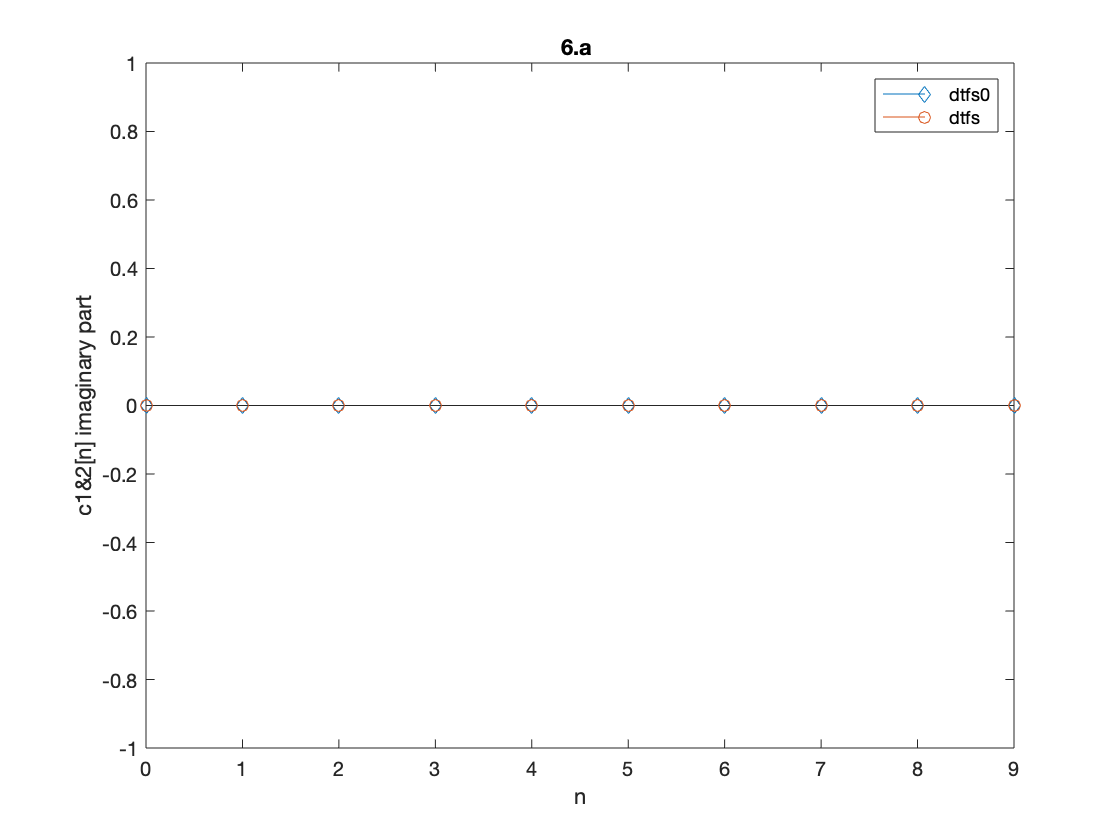

figure(12)
stem(n,c1i,"diamond")
hold on
stem(n,c2i)
hold off
xlabel('n')
ylabel('c1&2[n] imaginary part')
title('6.a '); 
legend('dtfs0','dtfs');

經過數值比較可看出兩者相等，驗證dtfs0 function正確

## 6.b

inverse DTFS：

x[n]=$\sum_{k=0}^{N-1} C_k e^{j\frac{2\pi }{N}\mathrm{kn}}$

Write a function x=idtfs0(c)：

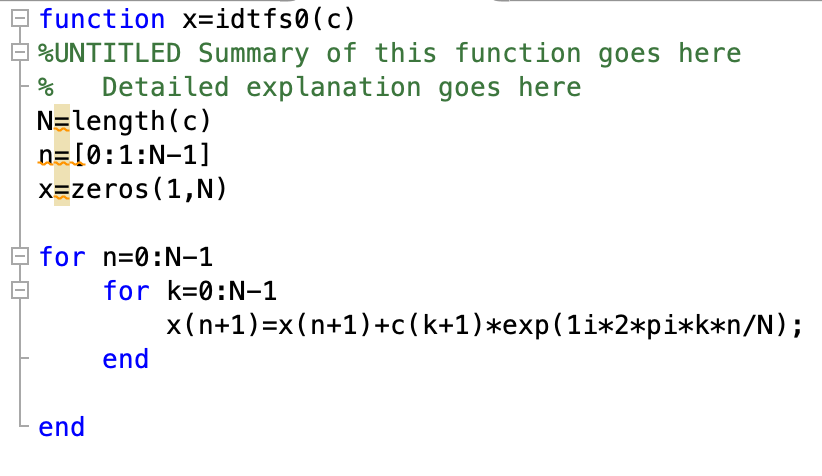

設定一組input c[n]，代入function idtfs0與idtfs做比較：

c=[0.5,0.3236,0,-0.1236,0,0.1,0,-0.1236,0,0.3236];
n=0:1:9;
x1=idtfs0(c);
x2=idtfs(c);

idtfs0與idtfs所得到的inverse function分別為x1和x2，下方將x1和x2的實虛部分開做比較，只將虛部取到小數點後5位做比較：

x1r=real(x1)

x1r =     1.0000    1.0000    1.0000    0.0000    0.0000         0    0.0000    0.0000    1.0000    1.0000


x2r=real(x2)

x2r =     1.0000    1.0000    1.0000    0.0000    0.0000         0    0.0000    0.0000    1.0000    1.0000


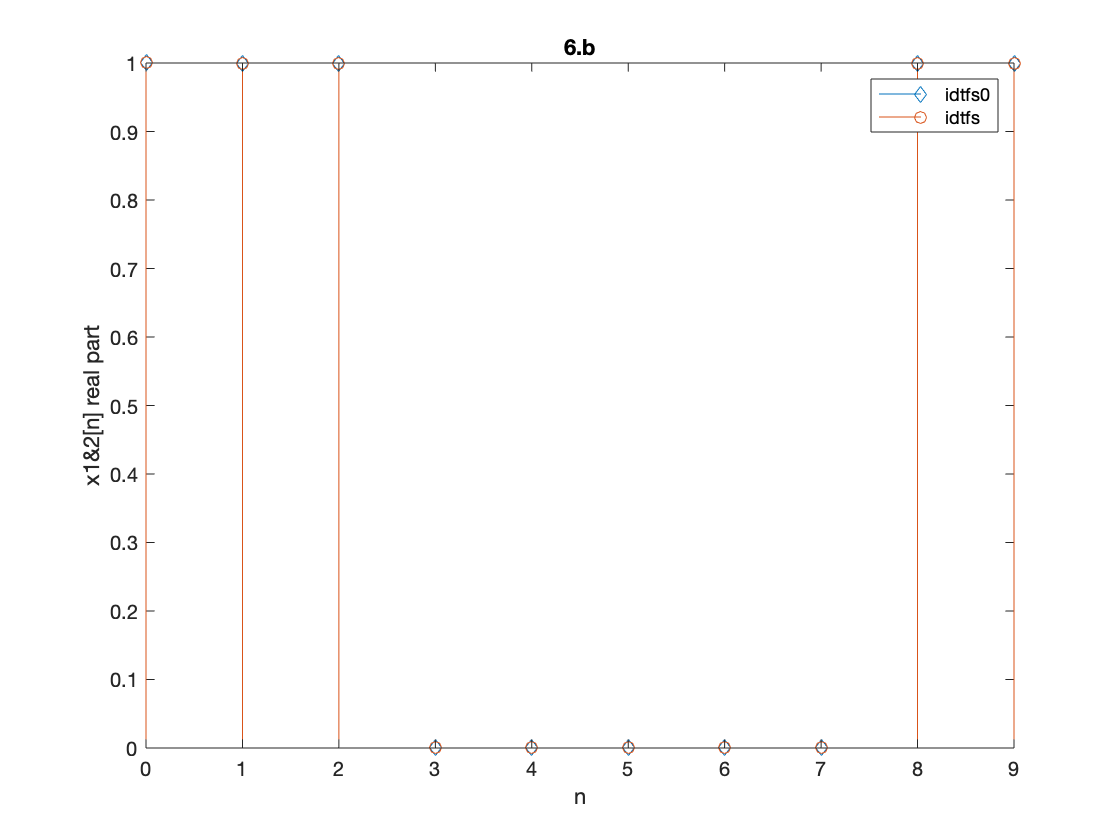

figure(13)
stem(n,x1r,"diamond")
hold on
stem(n,x2r)
hold off
xlabel('n')
ylabel('x1&2[n] real part')
title('6.b'); 
legend('idtfs0','idtfs');

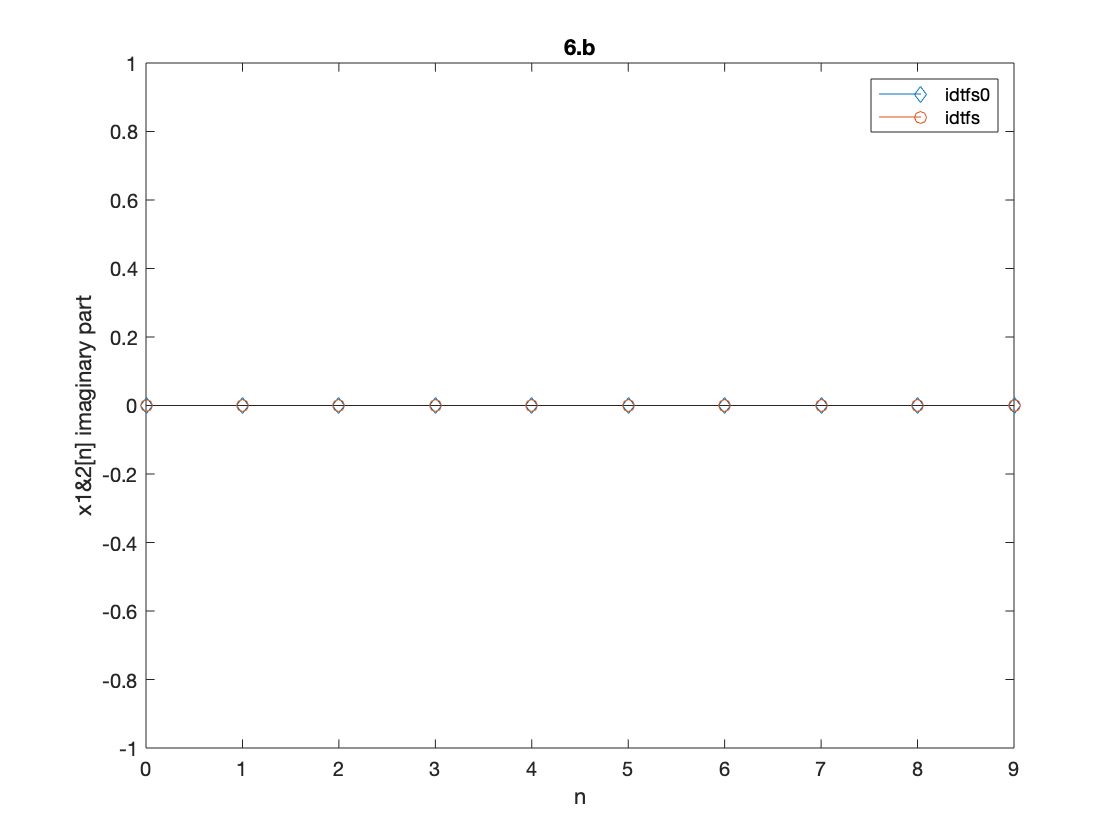

c=[0.5,0.3236,0,-0.1236,0,0.1,0,-0.1236,0,0.3236];
n=0:1:9;
x1=idtfs0(c);
x2=idtfs(c);
x1i=imag(x1);
x1i=roundn(x1i,-5);
x2i=imag(x2);

figure(14)
stem(n,x1i,"diamond")
hold on
stem(n,x2i)
hold off
xlabel('n')
ylabel('x1&2[n] imaginary part')
title('6.b'); 
legend('idtfs0','idtfs');

經過數值比較可看出兩者相等，驗證idtfs0 function正確

## 7.a

先將x[n]經過z transform得到transfer function的coefficients `b` and `a`


$$\begin{array}{l}
x_1 \left\lbrack n\right\rbrack =4\left(\cos \left(1\ldotp 2\pi n\right)\cos \left(\frac{\pi }{3}\right)-\sin \left(1\ldotp 2\pi n\right)\sin \left(\frac{\pi }{3}\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;+6\left(\sin \left(0\ldotp 4\pi n\right)\cos \left(\frac{\pi }{6}\right)-\cos \left(0\ldotp 4\pi n\right)\sin \left(\frac{\pi }{6}\right)\right)\\
\;\;\;\;\;\;\;\;\;\;=4\left(\frac{1}{2}\cos \left(1\ldotp 2\pi n\right)-\frac{\sqrt{3}}{2}\sin \left(1\ldotp 2\pi n\right)\right)\\
\;\;\;\;\;\;\;\;\;\;+6\left(\frac{\sqrt{3}}{2}\sin \left(0\ldotp 4\pi n\right)-\frac{1}{2}\cos \left(0\ldotp 4\pi n\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;=2\cos \left(1\ldotp 2\pi n\right)-2\sqrt{3}\sin \left(1\ldotp 2\pi n\right)+3\sqrt{3}\sin \left(0\ldotp 4\pi n\right)-3\cos \left(0\ldotp 4\pi n\right)\\
X_1 \left(Z\right)=2\left(\frac{1-\left(\cos \left(1\ldotp 2\pi \right)\right)Z^{-1} }{1-2\cos \left(1\ldotp 2\pi \right)Z^{-1} +Z^{-2} }\right)-2\sqrt{3}\left(\frac{\sin \left(1\ldotp 2\pi \right)Z^{-1} }{1-2\cos \left(1\ldotp 2\pi \right)Z^{-1} +Z^{-2} }\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;+3\sqrt{3}\left(\frac{\sin \left(0\ldotp 4\pi \right)Z^{-1} }{1-2\cos \left(0\ldotp 4\pi \right)Z^{-1} +Z^{-2} }\right)-3\left(\frac{1-\left(\cos \left(0\ldotp 4\pi \right)\right)Z^{-1} }{1-2\cos \left(0\ldotp 4\pi \right)Z^{-1} +Z^{-2} }\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\frac{2-\left(2\left(\cos \left(1\ldotp 2\pi \right)\right)-2{\left.\sqrt{3}\sin \left(1\ldotp 2\pi \right)\right)Z}^{-1} \right.}{1-2\cos \left(1\ldotp 2\pi \right)Z^{-1} +Z^{-2} }\right)+\frac{-3+\left(3\left(\cos \left(0\ldotp 4\pi \right)\right){+3\sqrt{3}\sin \left(0\ldotp 4\pi \right)} \right)Z^{-1} }{1-2\cos \left(0\ldotp 4\pi \right)Z^{-1} +Z^{-2} }
\end{array}$$


a1=[1 -2*cos(1.2*pi) 1];
a2=[1 -2*cos(0.4*pi) 1];
a=conv(a1,a2)

a =     1.0000    1.0000    1.0000    1.0000    1.0000


b11=[2 -2*cos(1.2*pi)-2*(3)^0.5*sin(1.2*pi)];
b12=[1 -2*cos(0.4*pi) 1];
b1=conv(b11,b12)

b1 =     2.0000    2.4181   -0.2584    3.6542


b21=[-3 3*cos(0.4*pi)+3*(3)^0.5*sin(0.4*pi)];
b22=[1 -2*cos(1.2*pi) 1];
b2=conv(b21,b22)

b2 =    -3.0000    1.0148    6.4961    5.8689


b=b1+b2

b =    -1.0000    3.4329    6.2376    9.5231



$$\begin{array}{l}
X_1 \left(Z\right)=\frac{\left(2+2\ldotp 4181Z^{-1} -0\ldotp 2584Z^{-2} +3\ldotp 6542Z^{-3} \right)+\left(-3+1\ldotp 0148Z^{-1} -6\ldotp 4961Z^{-2} +5\ldotp 8689Z^{-3} \right)}{1+Z^{-1} +Z^{-2} +Z^{-3} +Z^{-4} }\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{-1+3\ldotp 4329Z^{-1} +6\ldotp 2376Z^{-2} +9\ldotp 5231Z^{-3} }{1+Z^{-1} +Z^{-2} +Z^{-3} +Z^{-4} }
\end{array}$$


再將a/b代入freqz function畫出magnitude and phase：

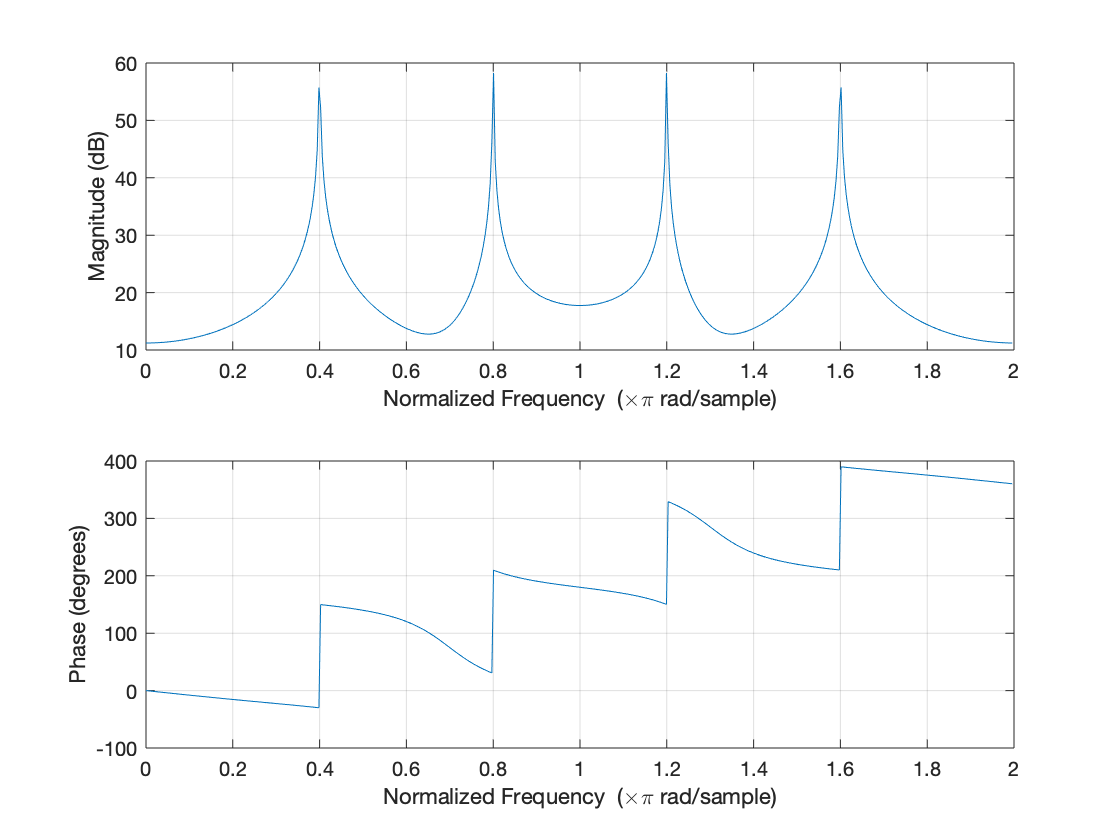

freqz(b,a,'whole')

## 7.b

此為causal sequence，因此可代入freqz function

x=[1,1,0,1,1,1,0,1]

x =      1     1     0     1     1     1     0     1


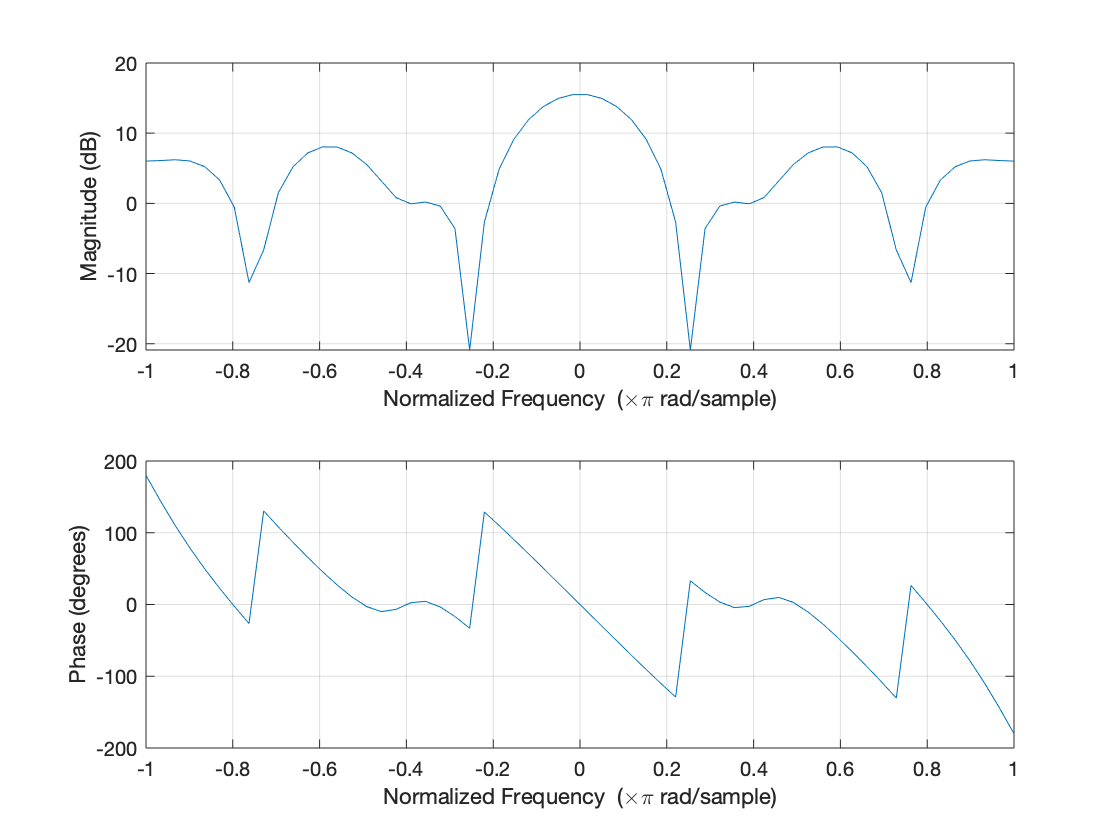

om=linspace(-pi, pi, 60); 
freqz(x, 1, om)

## 7.c

此為causal sequence，因此可代入freqz function

可是題目一個週期的x[n]，n是從0~11，與本身這個x的週期是不一樣的，我認為直接把x帶入freqz結果會不同，

因此設定n為0:1:11，這樣產生的x[n]就會是題目給的週期的值，再代入freqz function：

n=0:1:11

n =      0     1     2     3     4     5     6     7     8     9    10    11


x=1-sin(pi/4*n)

x =     1.0000    0.2929         0    0.2929    1.0000    1.7071    2.0000    1.7071    1.0000    0.2929         0    0.2929


om=linspace(-pi, pi, 60); 
freqz(x, 1, om)

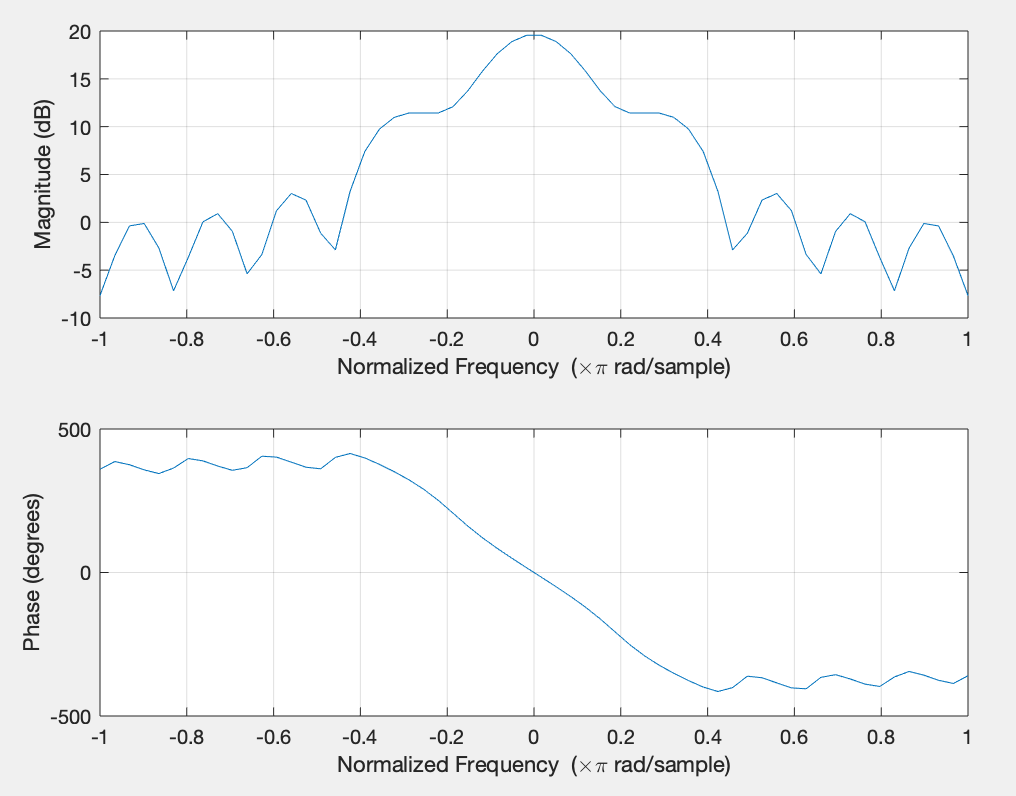

(因為9.a使用了close all後，這題的圖跑不出來，試了很多次沒辦法解決，

因此我直接在command window執行後用截圖的）

## 8.a

x=[1 1 1];
n=[-1,0,1];
om=linspace(-pi, pi, 60); 
X1=dtft12(x, -1, om);
X2=freqz(x, 1, om);

利用abs function取得X1和X2的magnitude，分別是a1和a2，單位使用dB，

phase則使用angle funtion取得，分別p1和p2

a1=10*log(abs(X1));
p1=angle(X1);
a2=10*log(abs(X2));
p2=angle(X2);
ax=om/pi;

figure(15)
subplot(2,1,1)
stem(ax,a1)
hold on
stem(ax,a2)
hold off
title('8.a magnitude(dB)'); 
ylabel('magnitude (dB)')
legend('dtft12','freqz');
subplot(2,1,2)
stem(ax,p1)
hold on 
stem(ax,p2)
hold off
xlabel('*pi rad/sample')
ylabel('phase (degree)')
legend('dtft12','freqz');

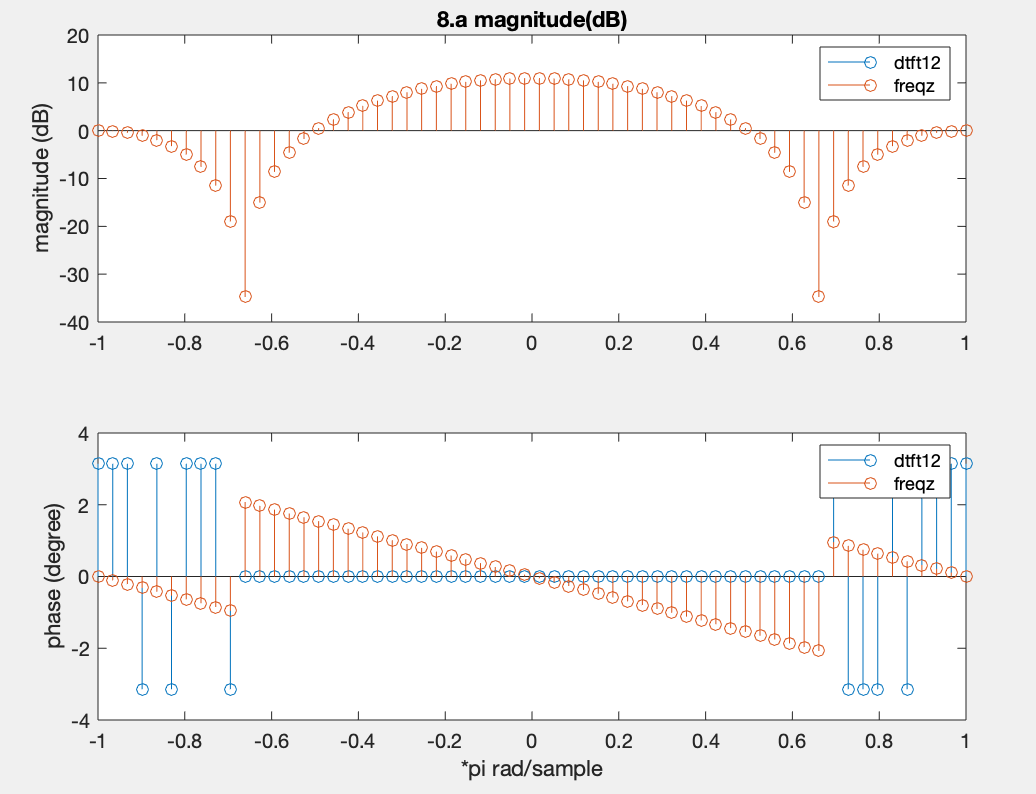

(因為9.a使用了close all後，這題的圖跑不出來，試了很多次沒辦法解決，

因此我直接在command window執行後用截圖的）

## 8.b

magnitude |X1| = |X2| , but phase ∠X1 $\not=$ ∠X2

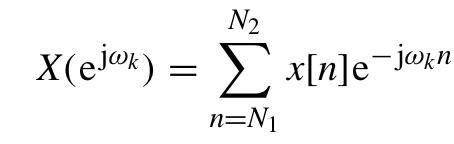

freqz function always assumes that $N_1 =0$,$N_2 =N$

But x[n] is a noncausal sequence, its first sample is at n=-1.

dtft12 changes the index of summation from n to m=n-$N_1$ :

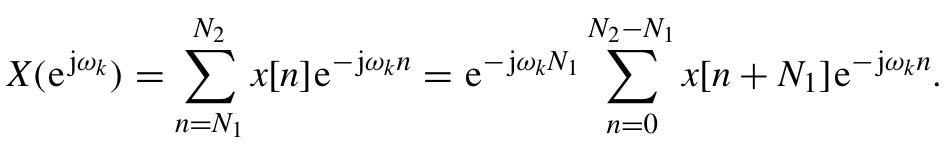

From the above equation is the answer that why there's a phase different between the two function.

For noncausal sequence using dtft12 is more suitable.

## 9.a

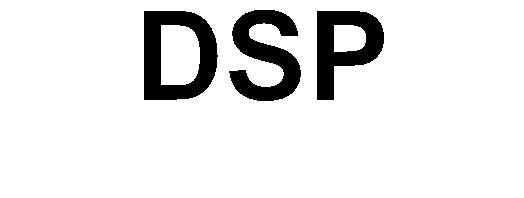

close all
clc

figure(16)
img = imread('DSP.png');
img=double(img);
imshow(img);

這是原本的圖檔，下方經過filter後：

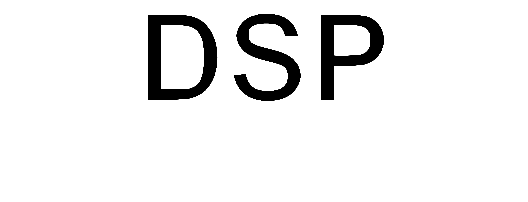

a=1/25;
h=[[a,a,a,a,a],
[a,a,a,a,a],
[a,a,a,a,a],
[a,a,a,a,a],
[a,a,a,a,a],];

y=conv2(img,h);
figure(17)
imshow(y)

h1是一個5x5的均值濾波器，他是一種平滑化濾波器，每一次濾波器h所涵蓋的原始影像的區域進行相乘，最後累加所有乘積，得到濾波影像y上一個像素的值，原本黑色字體邊緣值為0，與周圍相乘累加後，得到不為0的值，因此圖片中的字體看起來像是變細了

## 9.b

img = imread('DSP.png');
h1=[[1,0,-1],
    [2,0,-2],
    [1,0,-1]];
h2=[[1,2,1],
    [0,0,0],
    [-1,-2,-1]];

將經過h1和h2 conv2後的結果設為y1和y2

y1=conv2(img,h1);
y2=conv2(img,h2);

y1=abs(y1);
y1=uint8(y1);
y2=abs(y2);
y2=uint8(y2);

Then show y1 and y2:

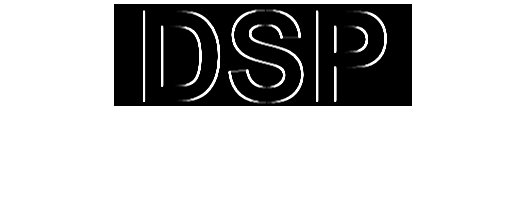

figure(18)
imshow(y1)

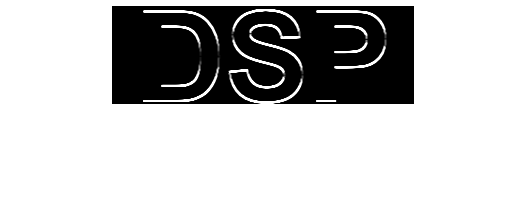

figure(19)
imshow(y2)

Sobel濾波器使用空間一階導數來增強高頻的空間訊號，在”DSP“這張圖中，這些高頻訊號代表字體的邊緣。

h1/h2分別為横向及縱向的一階導數Gx及Gy，Gx及Gy分別負責檢知X與Y方向的邊緣變化，

如果加總的Gx/Gy為0，代表其相鄰的點都是相同值，表示沒有邊緣變化，儲存的值就會是0，圖片點就呈現黑色，

如果左右的值不同，Gx/Gy輸出結果就不會是0，

經過h1/h2濾波所產生的結果，圖片就會進行橫向/縱向的比較，高梯度的地方會以白色的線表示，

經過h1處理後的圖，若左右點顏色相同就會顯現黑色，經過h2處理後的圖，若上下點顏色相同就會顯現黑色。

## 9.c

img = imread('DSP.png');
h1=[[1,0,-1],
    [2,0,-2],
    [1,0,-1]];
h2=[[1,2,1],
    [0,0,0],
    [-1,-2,-1]];

將經過h1和h2 filter2後的結果設為y1和y2

y1=filter2(h1,img);
y2=filter2(h2,img);

y1=abs(y1);
y1=uint8(y1);
y2=abs(y2);
y2=uint8(y2);

Then show y1 and y2:

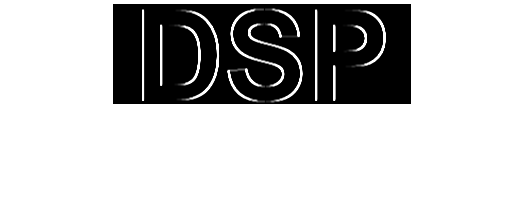

figure(16)
imshow(y1)

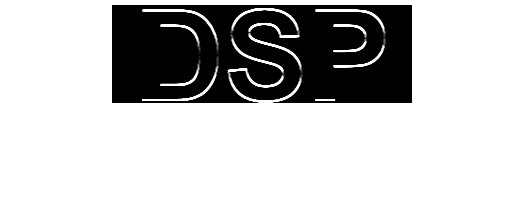

figure(17)
imshow(y2)

filter2 is basically the same with conv2, but the output sequence of filter2 is the same size as the input seqeunce.

img=100X300

for using conv2 output=102X302

for using filter2 output=100X300

So more suitable function for FIR spatial filtering is filter2.

## 10.a

使用downsample function每隔2個sample取1個，原本的Fs會變成1/2倍，

處理後的音訊設為playerObj1

Fs=8192;
[y,Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
y1=downsample(y,2);
playerObj1 = audioplayer(y1, Fs/2);
play(playerObj1);

## 10.b

使用downsample function每隔4個sample取1個，原本的Fs會變成1/4倍，

處理後的音訊設為playerObj2

Fs=8192;
[y,Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
y2=downsample(y,4);
playerObj2 = audioplayer(y2, Fs/4);
play(playerObj2);

## 10.c

10.b取的sample數是原本的1/2倍，10.c取的sample數是原本的1/4倍，sampling rate越小，會造成音訊聽起來越不清晰